# Building Energy Management Overview

The process considered here is a thermal model of rooms in a building with a central heating and cooling system to provide comfort when the outdoor environment varies temperature, $T_{outdoor}$, throughout the day.  Comfort is characterized by meeting the set point temperature, $T_{set}$, for the inside of the room(s), but the controller should also consider minimizing the cost. Heating is four times as expensive as cooling, which reflects how typically energy bills are more expensive in Winter. Building energy management can get tough when using the same controller through different seasons and rooms with different heat losses due to number of windows.

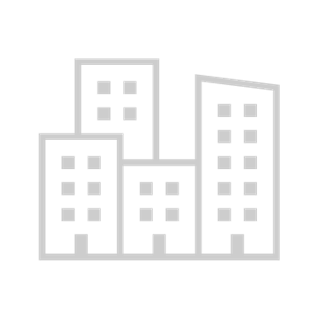

This example shows how to use Project Bonsai’s Machine Teaching strategies to learn a controller to balance comfort and cost for heating and cooling rooms with various equivalent thermal resistances and outdoor environment. This sample is largely adapted from the MathWorks’ [Thermal model of a house](https://www.mathworks.com/help/simulink/slref/thermal-model-of-a-house.html).

## Model Overview

A room in the building is simulated as a dynamic model that calculates room temperature variations using Simulink. The timestep is fixed at 5 minute intervals for the solver, where the units are in hours. The equation takes into consideration the energy flow from the heater or air conditioner, $\frac{dQ_{in}}{dt}$,  and heat losses to the environment, $R_{eq}$.  


$$\frac{dT_{room}}{dt}=\frac{1}{M_{air}C}\left(\frac{dQ_{in}}{dt}-\left(\frac{T_{room}-T_{out}}{R_{eq}}\right)\right)$$


The mass of air inside the room, , and equivalent thermal resistance, $R_{eq}$, characterize rooms with different thermal properties from parameters such as 

- Room geometry (length, width, height of room)

- Number of windows

- Thermal properties of room materials like insulation capacitance, resistance, thickness

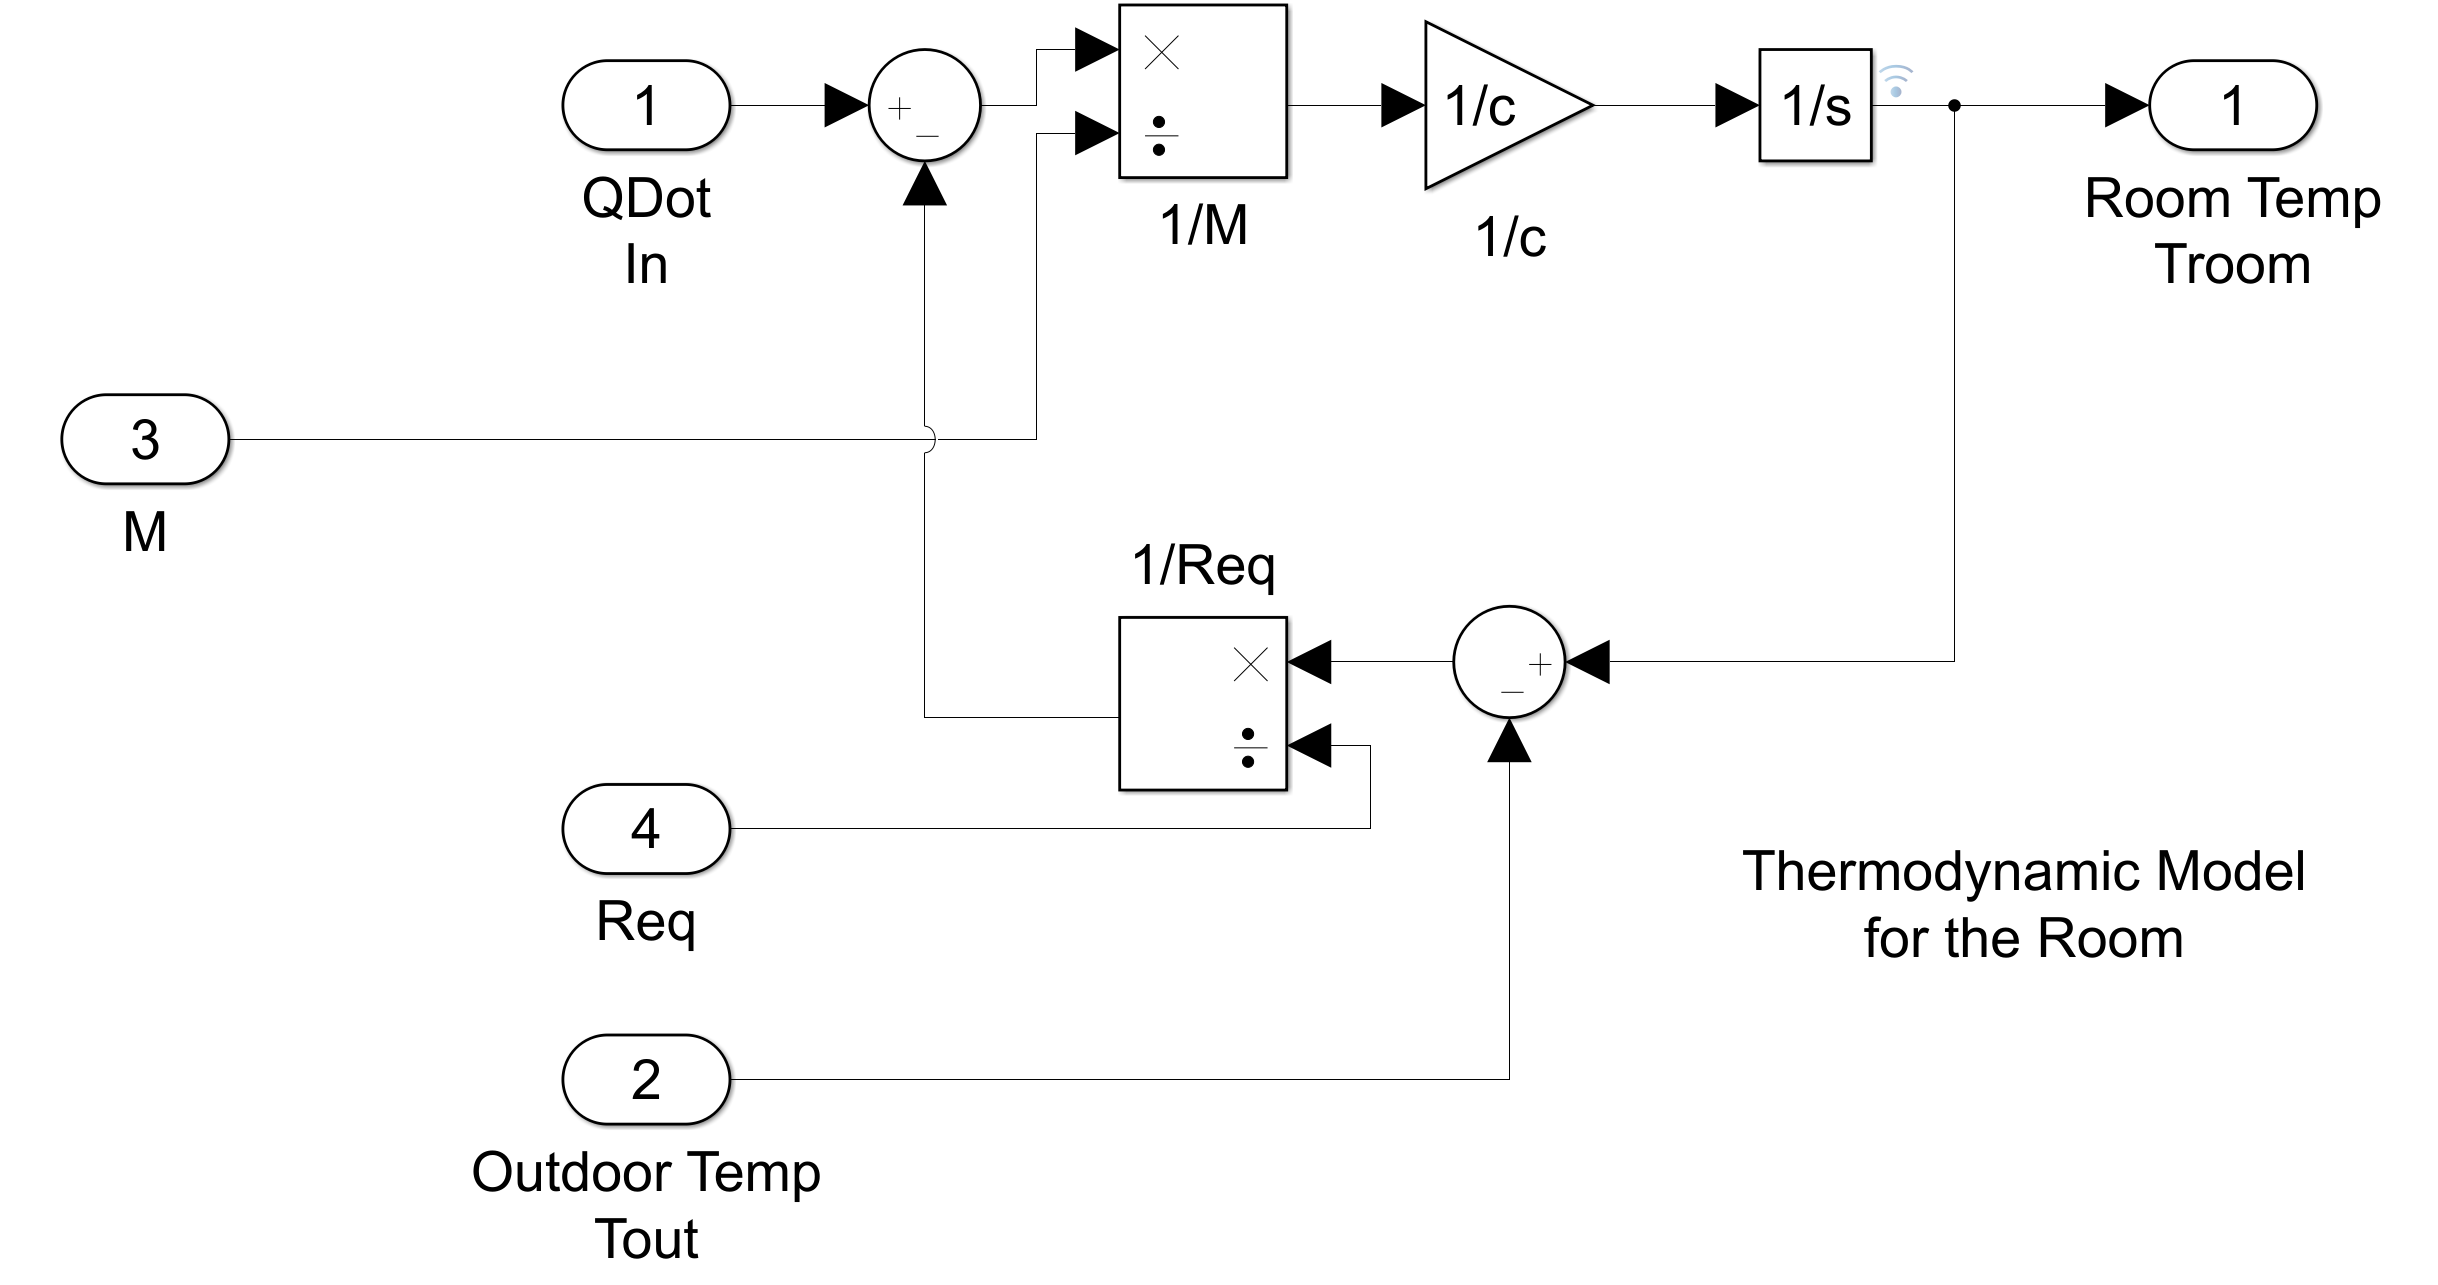

The heater subsystem models a constant air flow rate, $\dot{M}_{air}$, which is specified in the init_vars.m file. When the heater is selected, it blows hot air at temperature Theater (50 $^{\circ}C$ = 122 $^{\circ}F$ by default) at a constant flow rate of $\dot{M}_{air}$ (1  = 36000  $\frac{kg}{hr}$) . 


$$\frac{dQ_{in}}{dt}=\dot{M}_{air}C\left(T_{heater}-T_{room}\right)$$


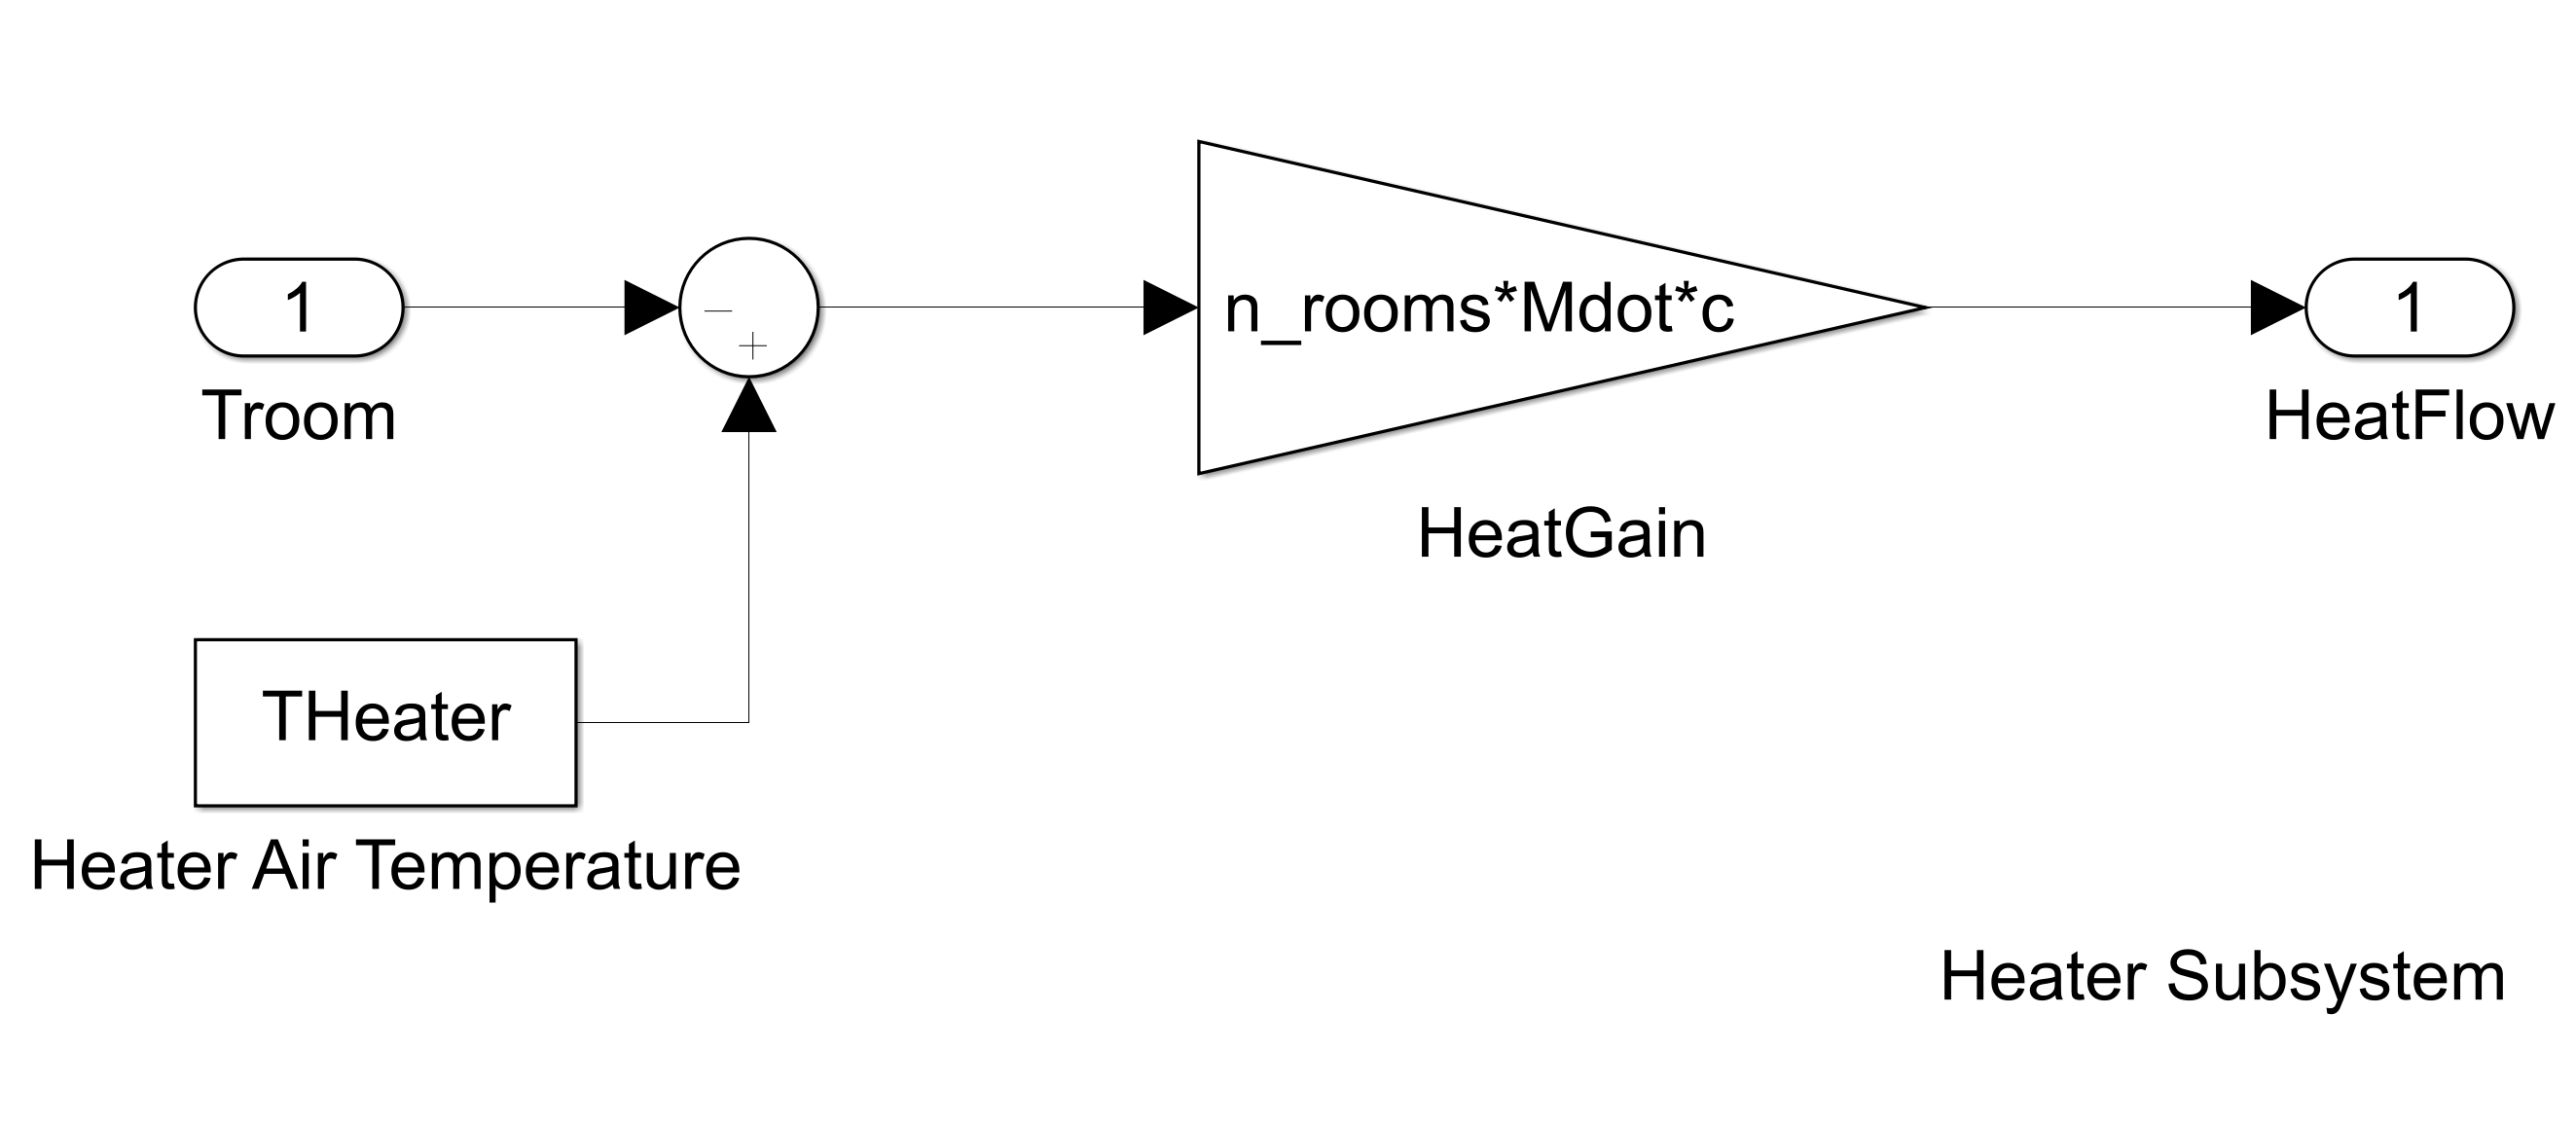

The energy flow can also remove heat from the room using the air conditioner subsystem. Using the same constant air flow rate, $\dot{M}_{air}$, the air conditioner blows cold air in such a way that the temperature difference between the room and the cold air is always (20 $^{\circ}C$ = 68 $^{\circ}F$). The efficiency of the air conditioning unit, $\eta$, is specified as 85%. 


$$\frac{dQ_{in}}{dt}=\dot{M}_{air}C\ \eta\left(T_{room}-\ 20-T_{room}\right)$$


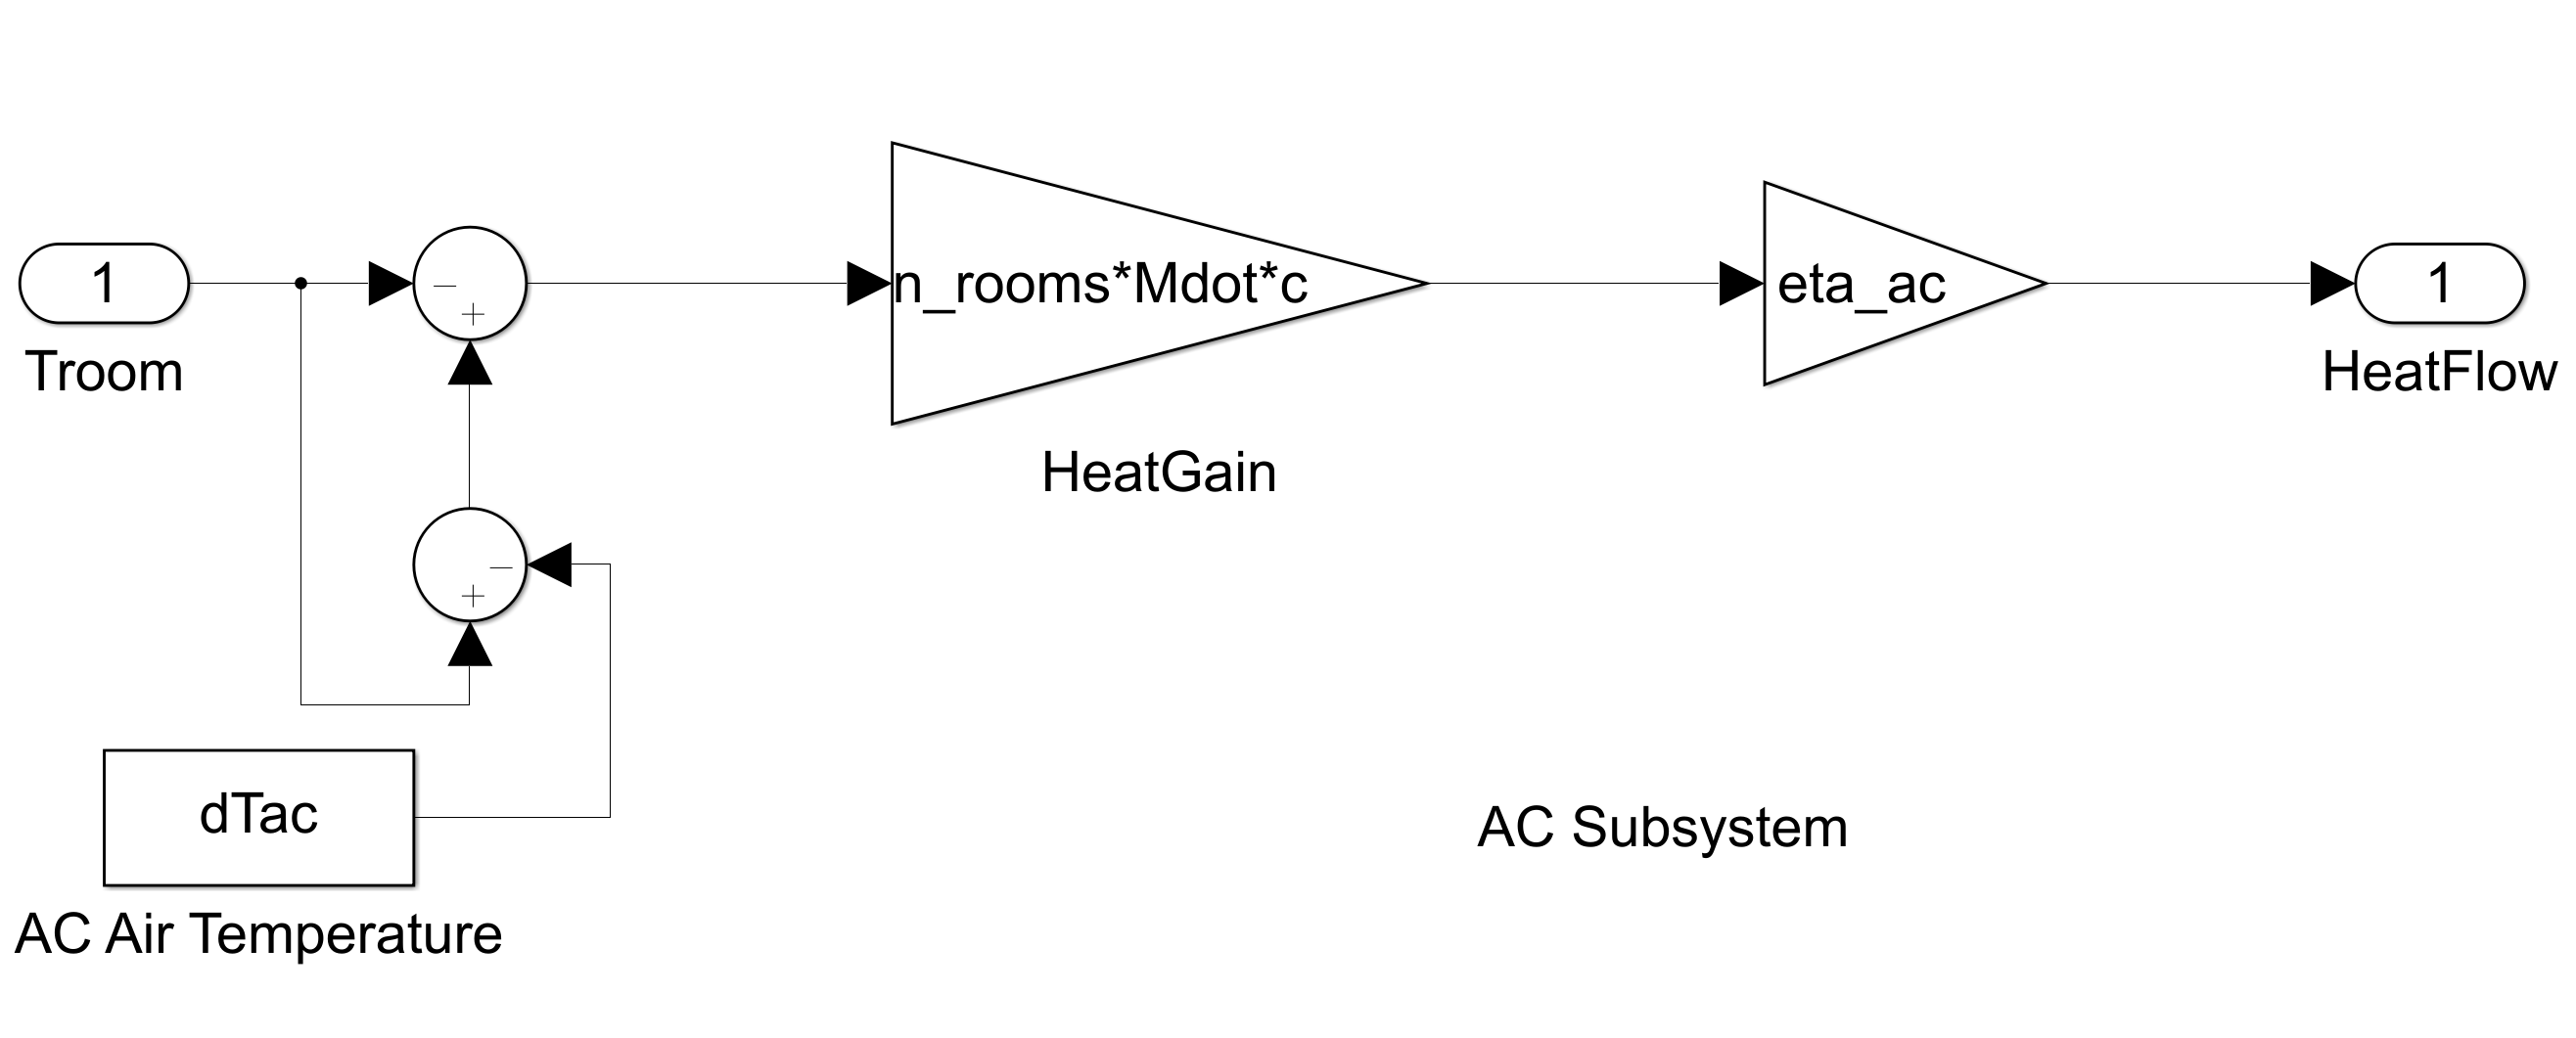

Thus far, the model has been simulated for a single room. If more rooms are introduced with various thermal properties, then the $\dot{M}_{air}$ is scaled accordingly and the central heating and cooling system splits the energy flow evenly into the number of rooms. This means that modeling multiple rooms in a building with this simulation consists of making copies of the room model and splitting the energy flow to make the problem more challenging since there is not individual control of heating and cooling per room. The average of the room temperatures is used as input to the heater and air conditioner subsystems to resemble limited control when more rooms are involved. 

The outdoor temperature is simulated as a sinusoid over the course of a day with a frequency of  $\frac{2 \pi}{24} \frac{rad}{s}$ and an amplitude of 15$^{\circ}F$ with a mean of varying outdoor temperatures. The cost of electricity is 9 cents per kWhr and is scaled depending on whether heating or cooling is used.

The following products are required to run the model:

- Simulink Version 10.0 (R2019b) or greater

- Bonsai [Toolbox ](http://aka.ms/as/bonsai-toolbox)0.1.4

- Bonsai [account](https://docs.microsoft.com/en-us/bonsai/quickstart/setup)

## Objectives and Constraints

The problem requires maintaining the room temperatures to be within 5$^{\circ}F$ above or below the desired set temperature. The set temperature schedules are based on [energy.gov](https://www.energy.gov/energysaver/thermostats) recommendations for thermostat settings. 

- Summer: 78 $^{\circ}F$ during the day, 86 $^{\circ}F$ at night

- Winter: 68 $^{\circ}F$ during the day, 60 $^{\circ}F$ at night

- In simulation, follow Summer $T_{set}$ if $T_{outdoor}$ > 73 $^{\circ}F$, else Winter $T_{set}$

The system can only use the air conditioner or heater one at a time. Once the method of energy flow is selected, it is required to continue to use it until the timestep of 5 minutes has passed. If the room temperature is within the target region, then choosing to turn off both the heater and air conditioner is also a valid option.

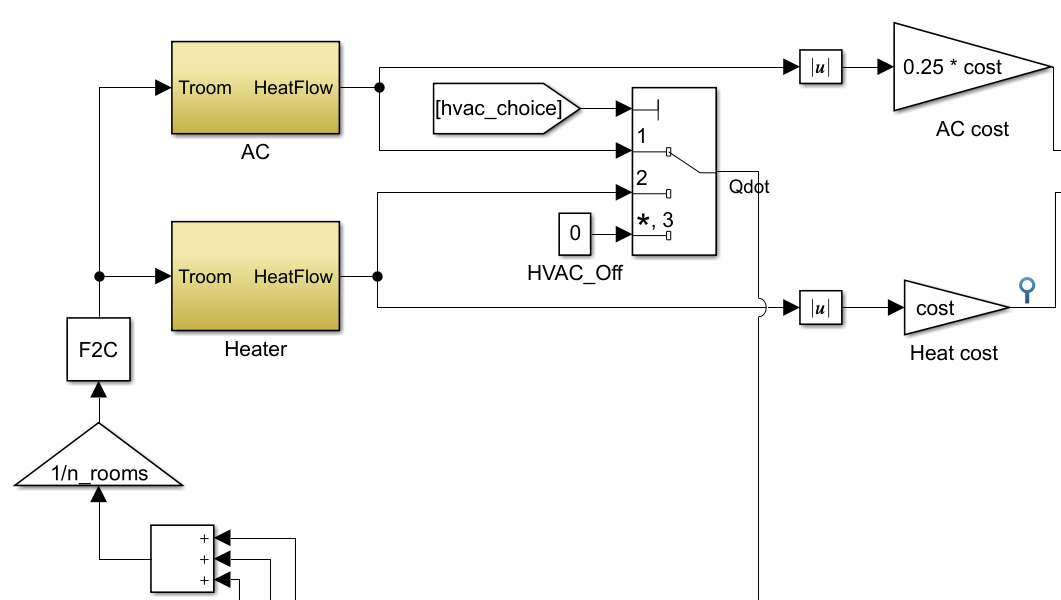

A discrete value of one will instruct a multiport switch block to use the air conditioner. A value of two will specify the usage of the heater blower. If neither the heater and air conditioner are desired, then a discrete value of 3 will send an energy flow of zero for the fixed timestep.

## Benchmark Controller

A thermostat is modeled using a Relay block, which allows fluctuations of 5 $^{\circ}F$ above or below the desired room temperature. The Relay block will output an on or off value by comparing the input to the specified thresholds. 

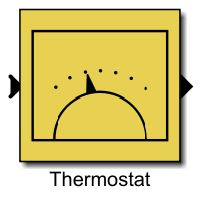

The on or off state of the relay is not affected by the input between the upper and lower limits. The switch off point must always be lower than the on point when using this block, so the air conditioning relay multiplies the temperature error by negative one. 

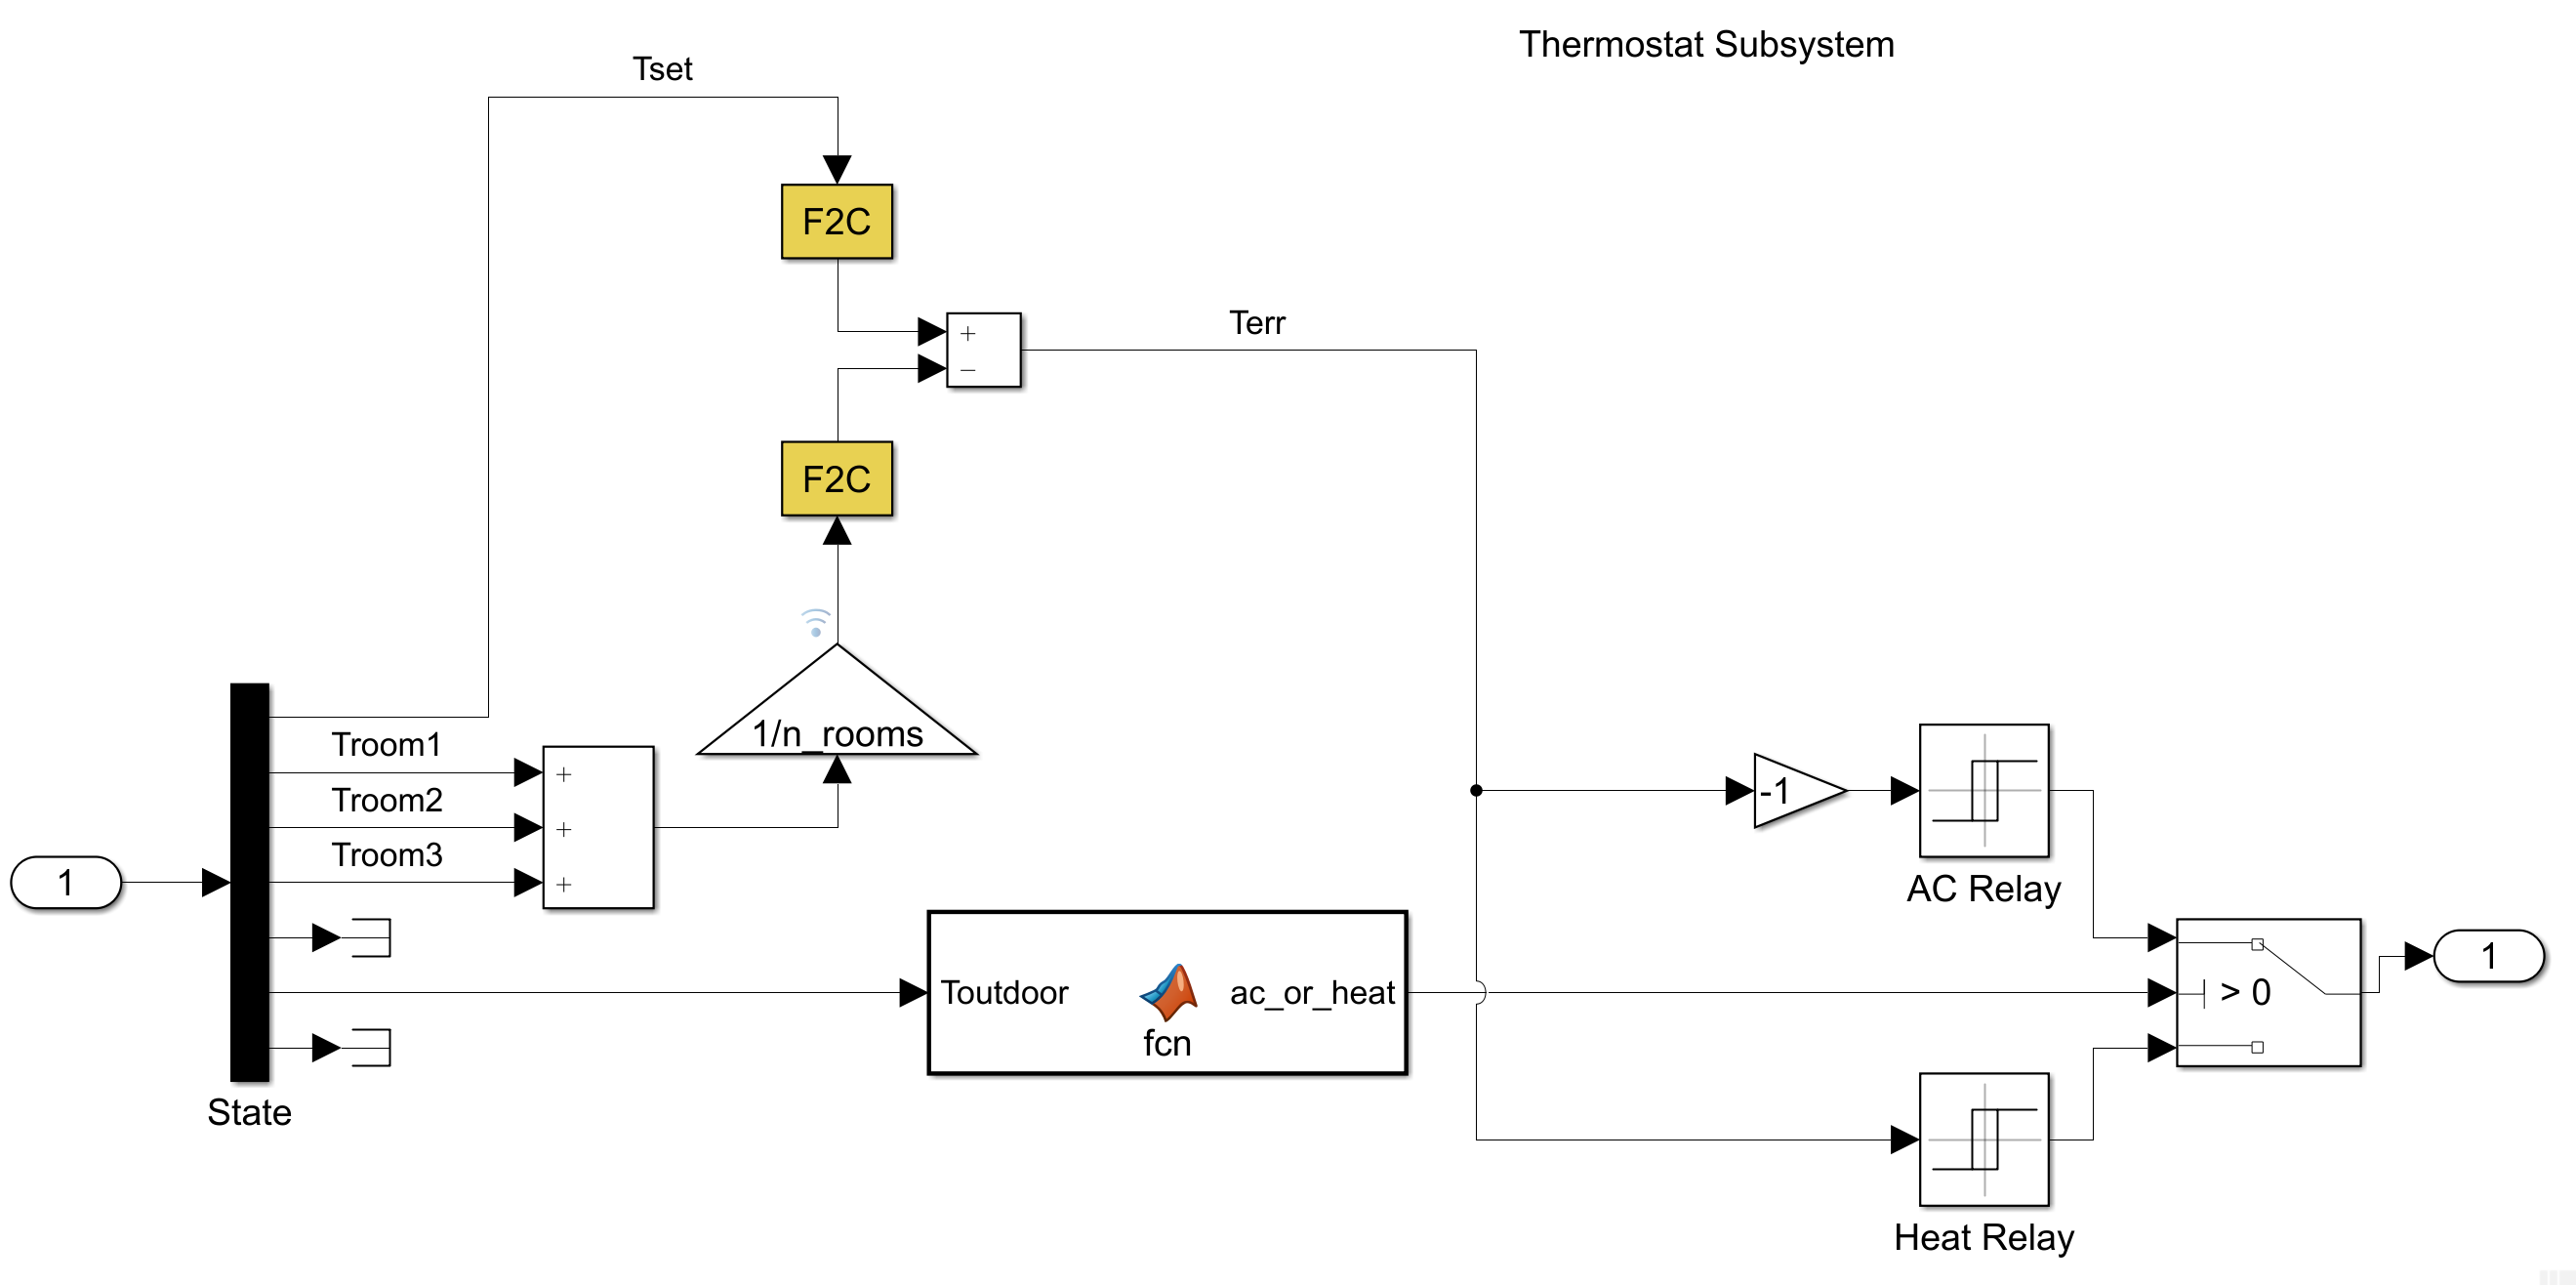

The outdoor temperature is used to instruct the thermostat to switch to heating or cooling with the threshold of being greater than 73$^{\circ}F$. This was found to be more beneficial than using the room temperature error in terms of heating or cooling at improper times throughout the day.

Evaluating the thermostat at a moderate day with Toutdoor = 60 $^{\circ}F$ can be quantified using a metric such as mean absolute error (mae) for a sequential decision making problem. This metric calculates the error from the set temperature at each timestep and basically aggregates the results throughout the day.

 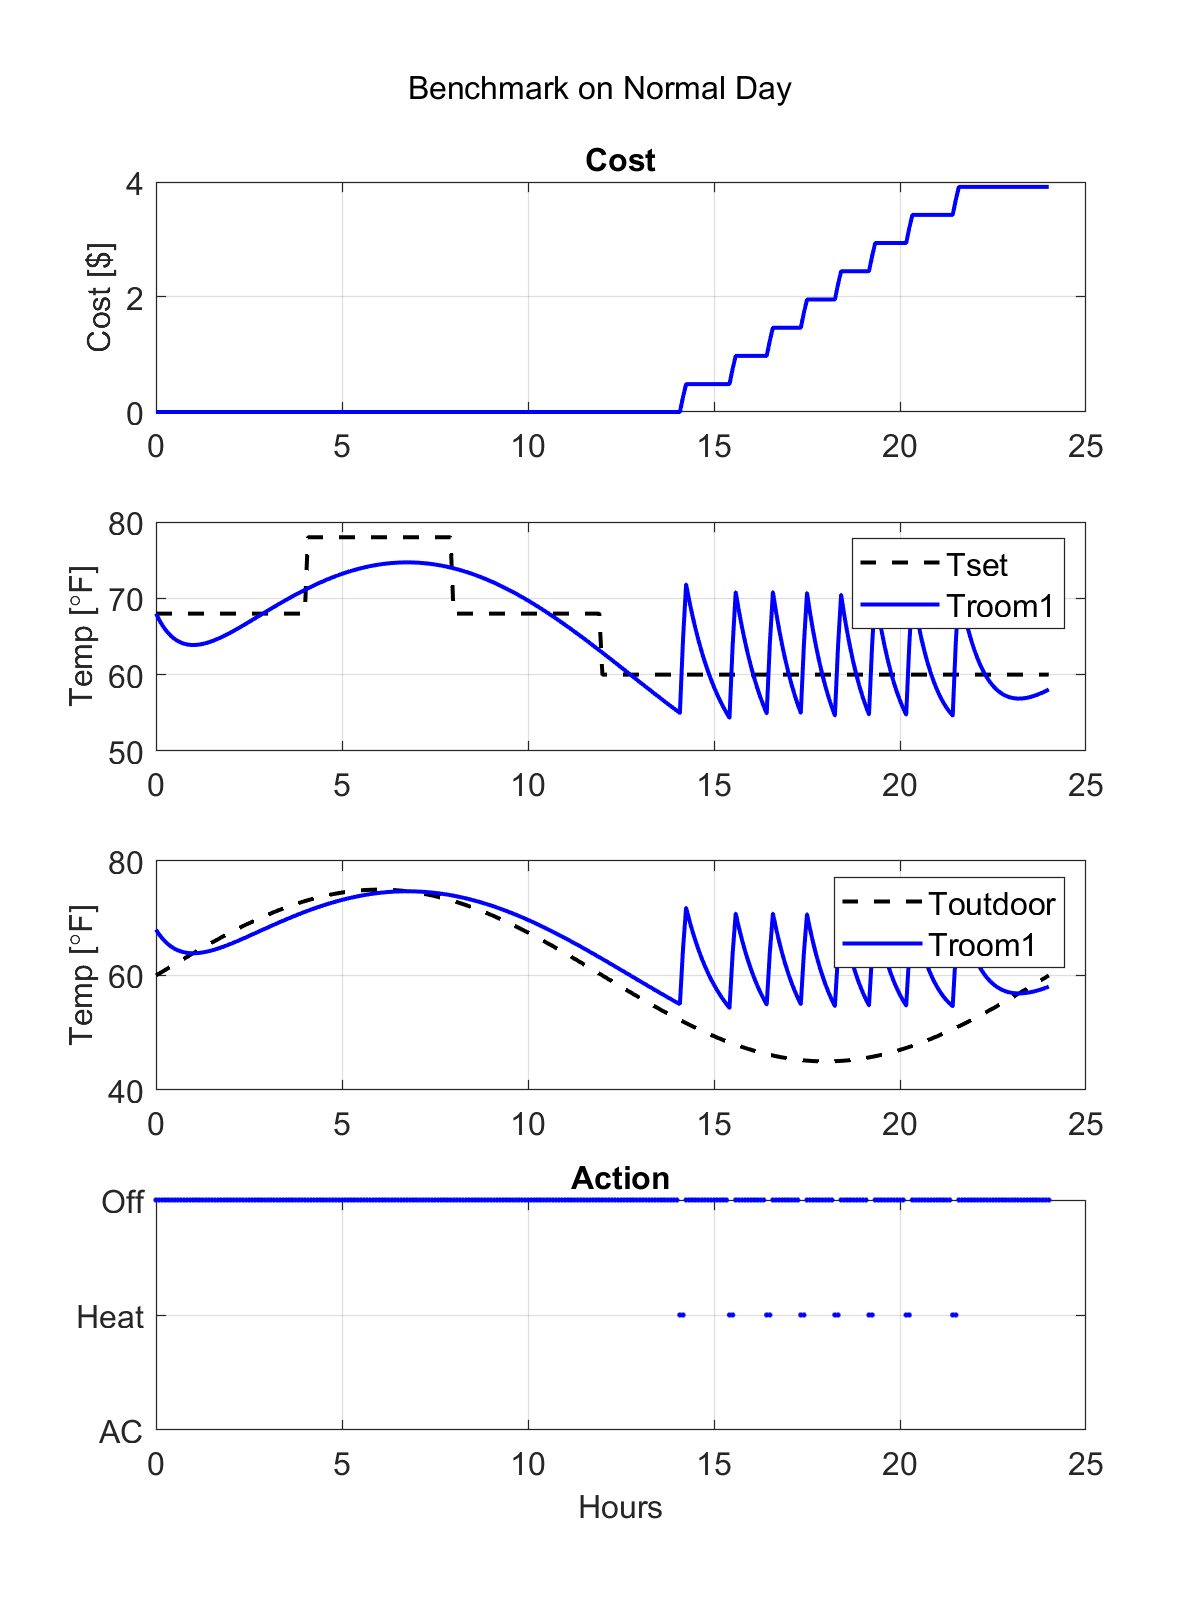


$$T_{outdoor}: 60 ^{\circ} F \\ 
T_{room} \ mae: 3.4517 ^{\circ} F \\
Cost: \$3.92 \\$$


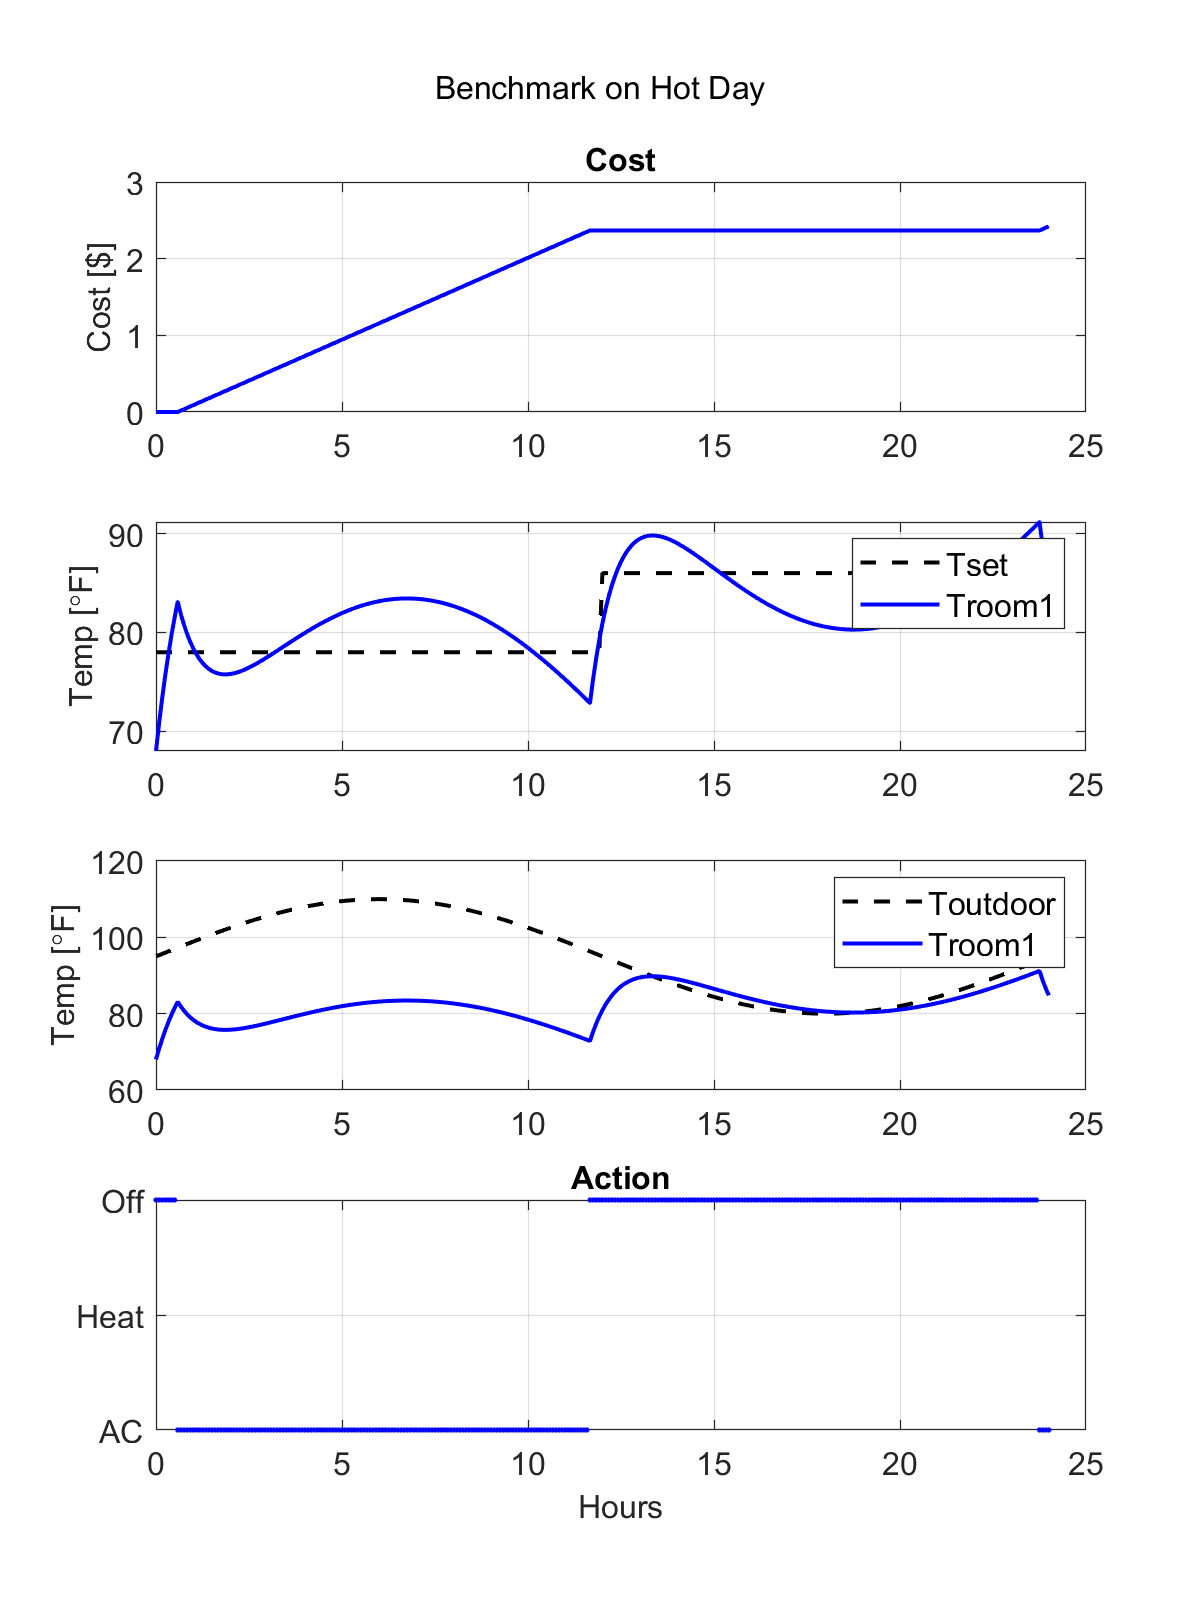


$$T_{outdoor}: 95 ^{\circ} F \\ 
T_{room} \ mae: 3.0913 ^{\circ} F \\
Cost: \$2.42 \\$$


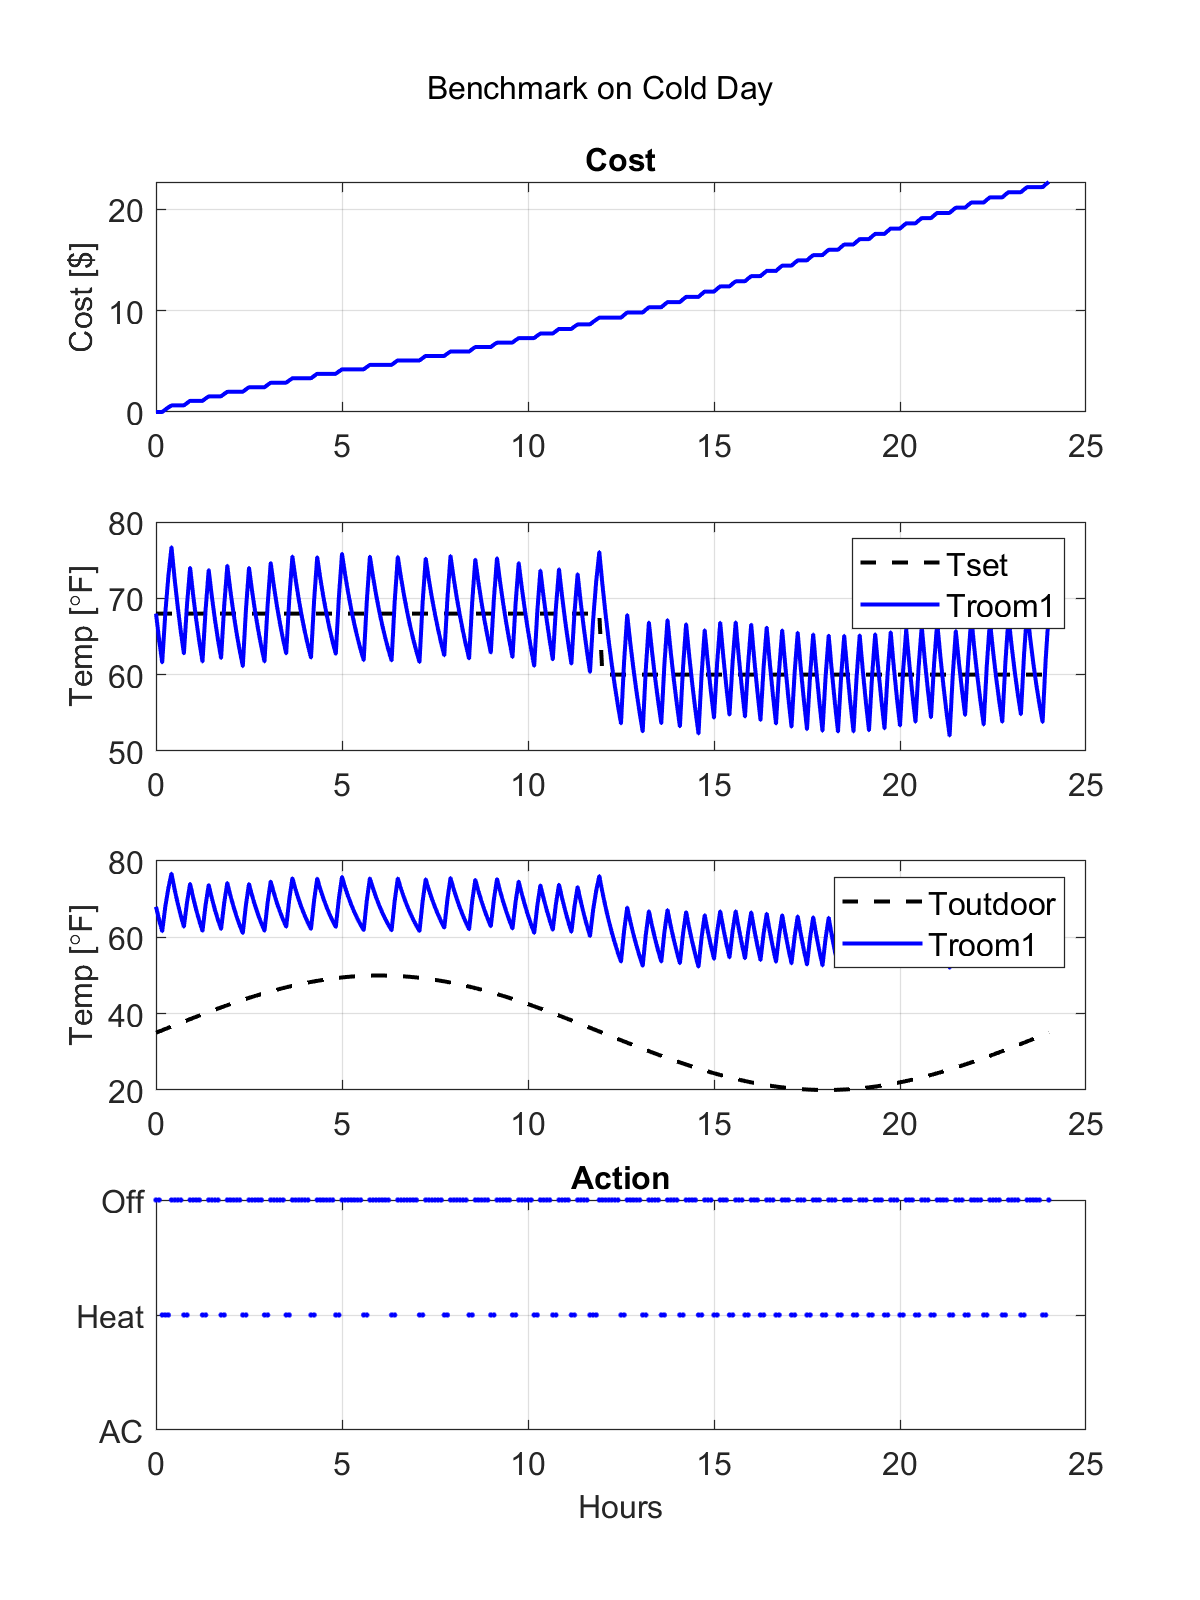


$$T_{outdoor}: 35 ^{\circ} F \\ 
T_{room} \ mae: 3.5867 ^{\circ} F \\
Cost: \$22.71 \\$$


## Machine Teaching Benefits

The thermostat is a traditional approach to heating and cooling buildings to maintain temperatures near the desired setpoint. Finding rules based approaches to switch between heating and cooling for different seasons can be a challenge when there is not a human in the loop to adjust schedules, which is especially true when trying to minimize costs. The challenge increases when multiple rooms are involved in a building because the problem becomes underactuated: a central air must supply adequate and average energy flow to various rooms of different sizes, windows, and heat losses. 

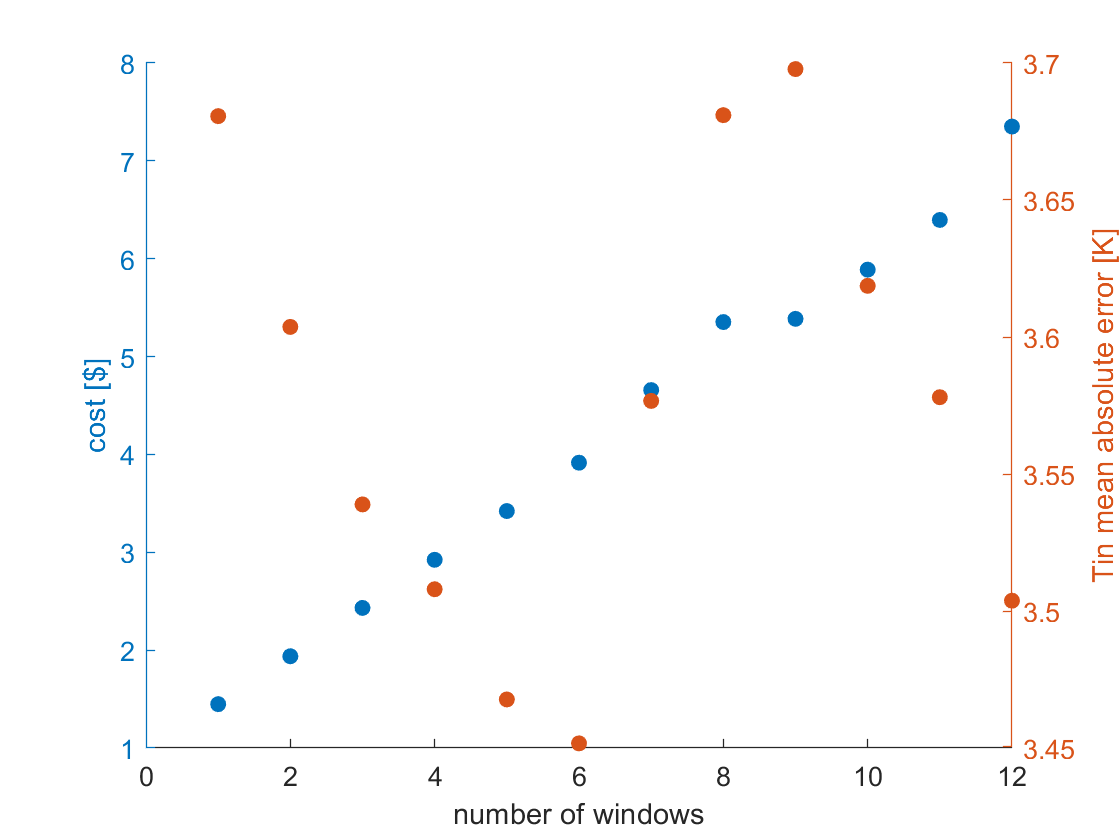

As the number of windows increases for a room, the cost increases because the room has higher heat losses. Having more windows increases the area of the room that has a higher thermal conductance, which decreases the equivalent thermal resistance in a simplified thermal circuit. The default number of windows used in the room thus far is six. 

Running the thermostat in a building with three rooms with a different number of windows for the moderate day begins to demonstrate how difficult it is to not have individual heating and cooling capabilities per room. Room one has three windows, room two has six windows, and room three has 12 windows.

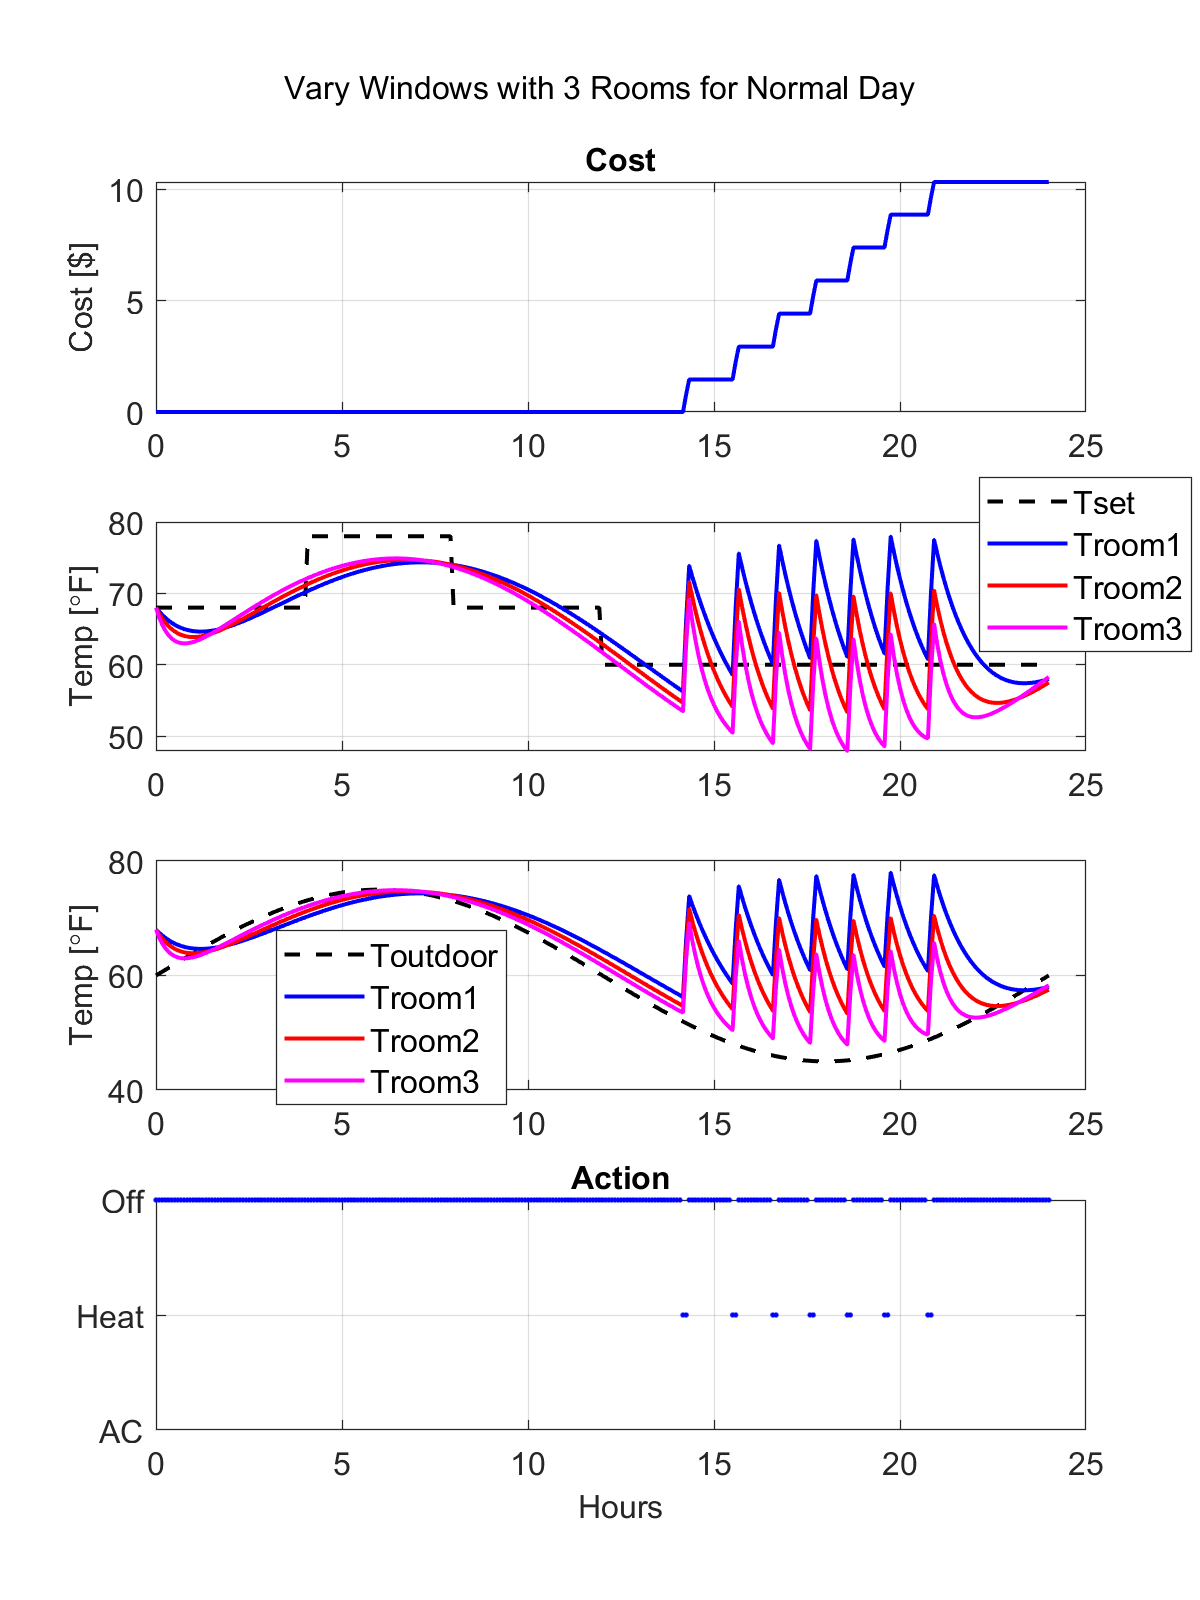


$$T_{outdoor}: 60 ^{\circ} F \\ 
T_{room1} \ mae: 4.5012 ^{\circ} F \\
T_{room2} \ mae: 3.5485 ^{\circ} F \\
T_{room3} \ mae: 4.2037 ^{\circ} F \\
Cost: \$10.32 \\$$


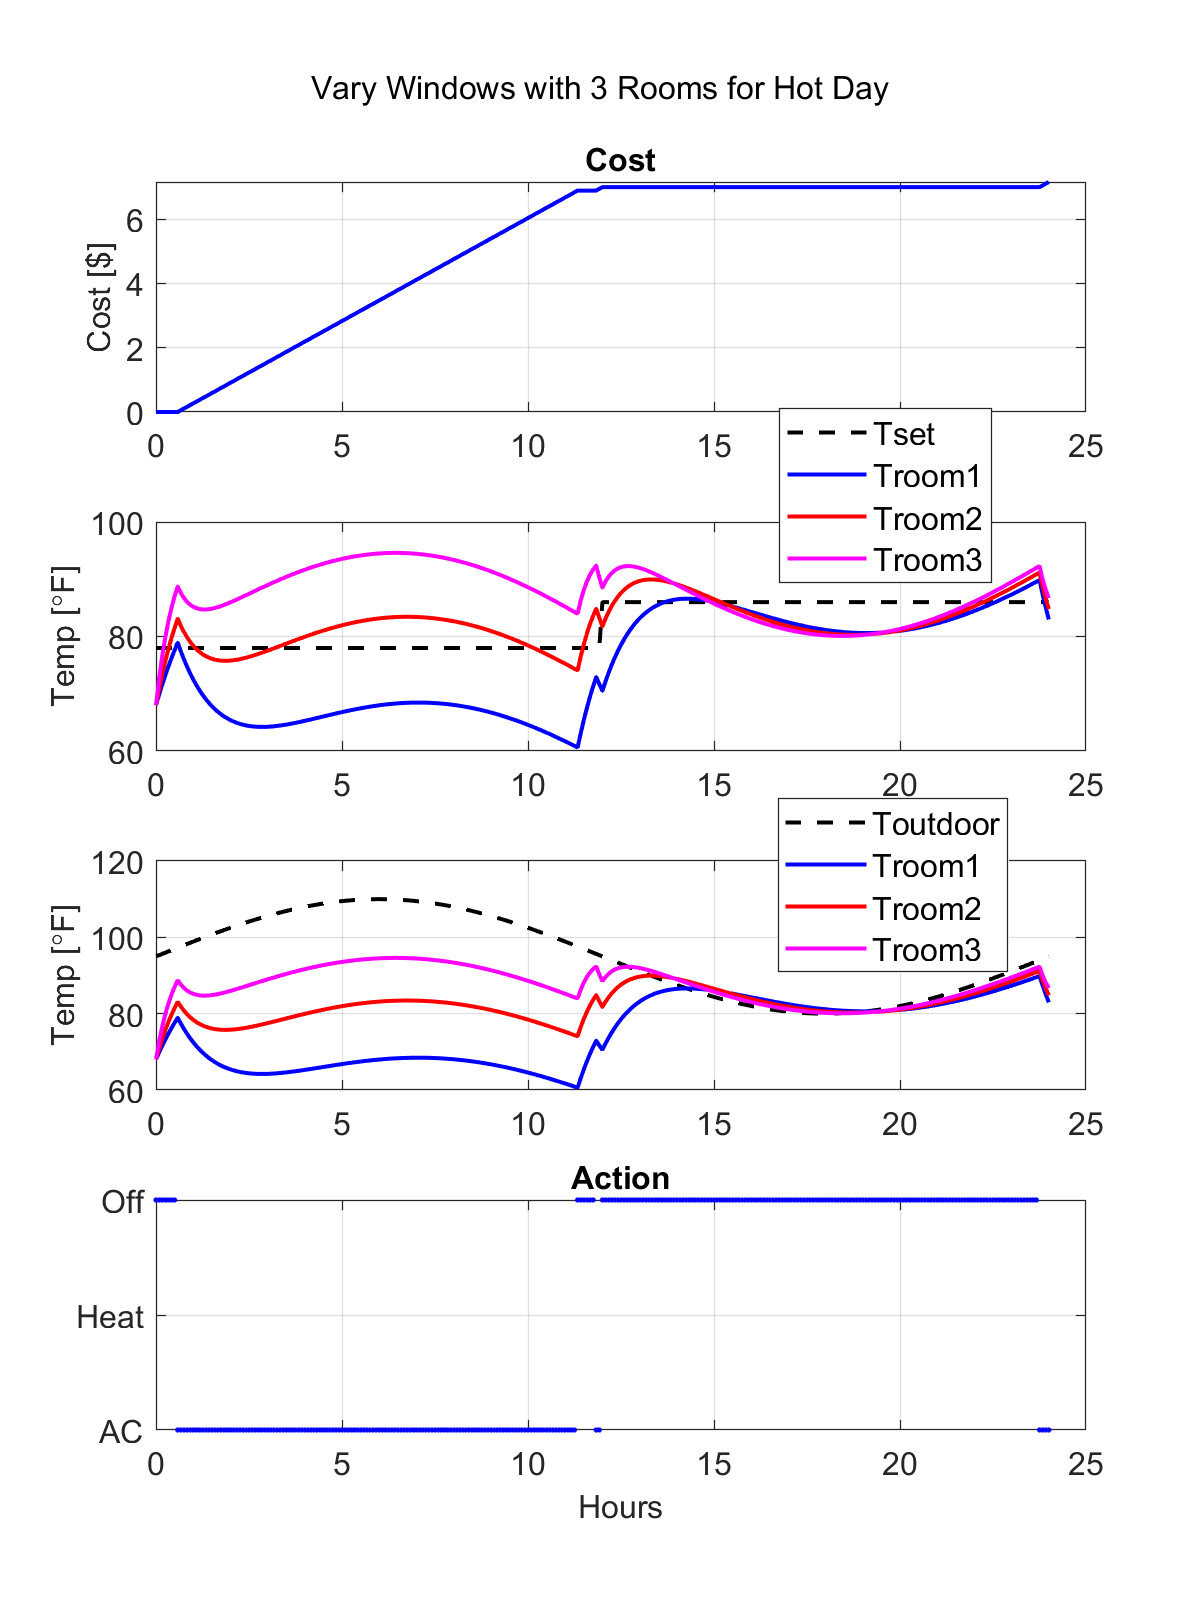


$$T_{outdoor}: 95 ^{\circ} F \\ 
T_{room1} \ mae: 7.0792 ^{\circ} F \\
T_{room2} \ mae: 3.1073 ^{\circ} F \\
T_{room3} \ mae: 7.8711 ^{\circ} F \\
Cost: \$7.16 \\$$


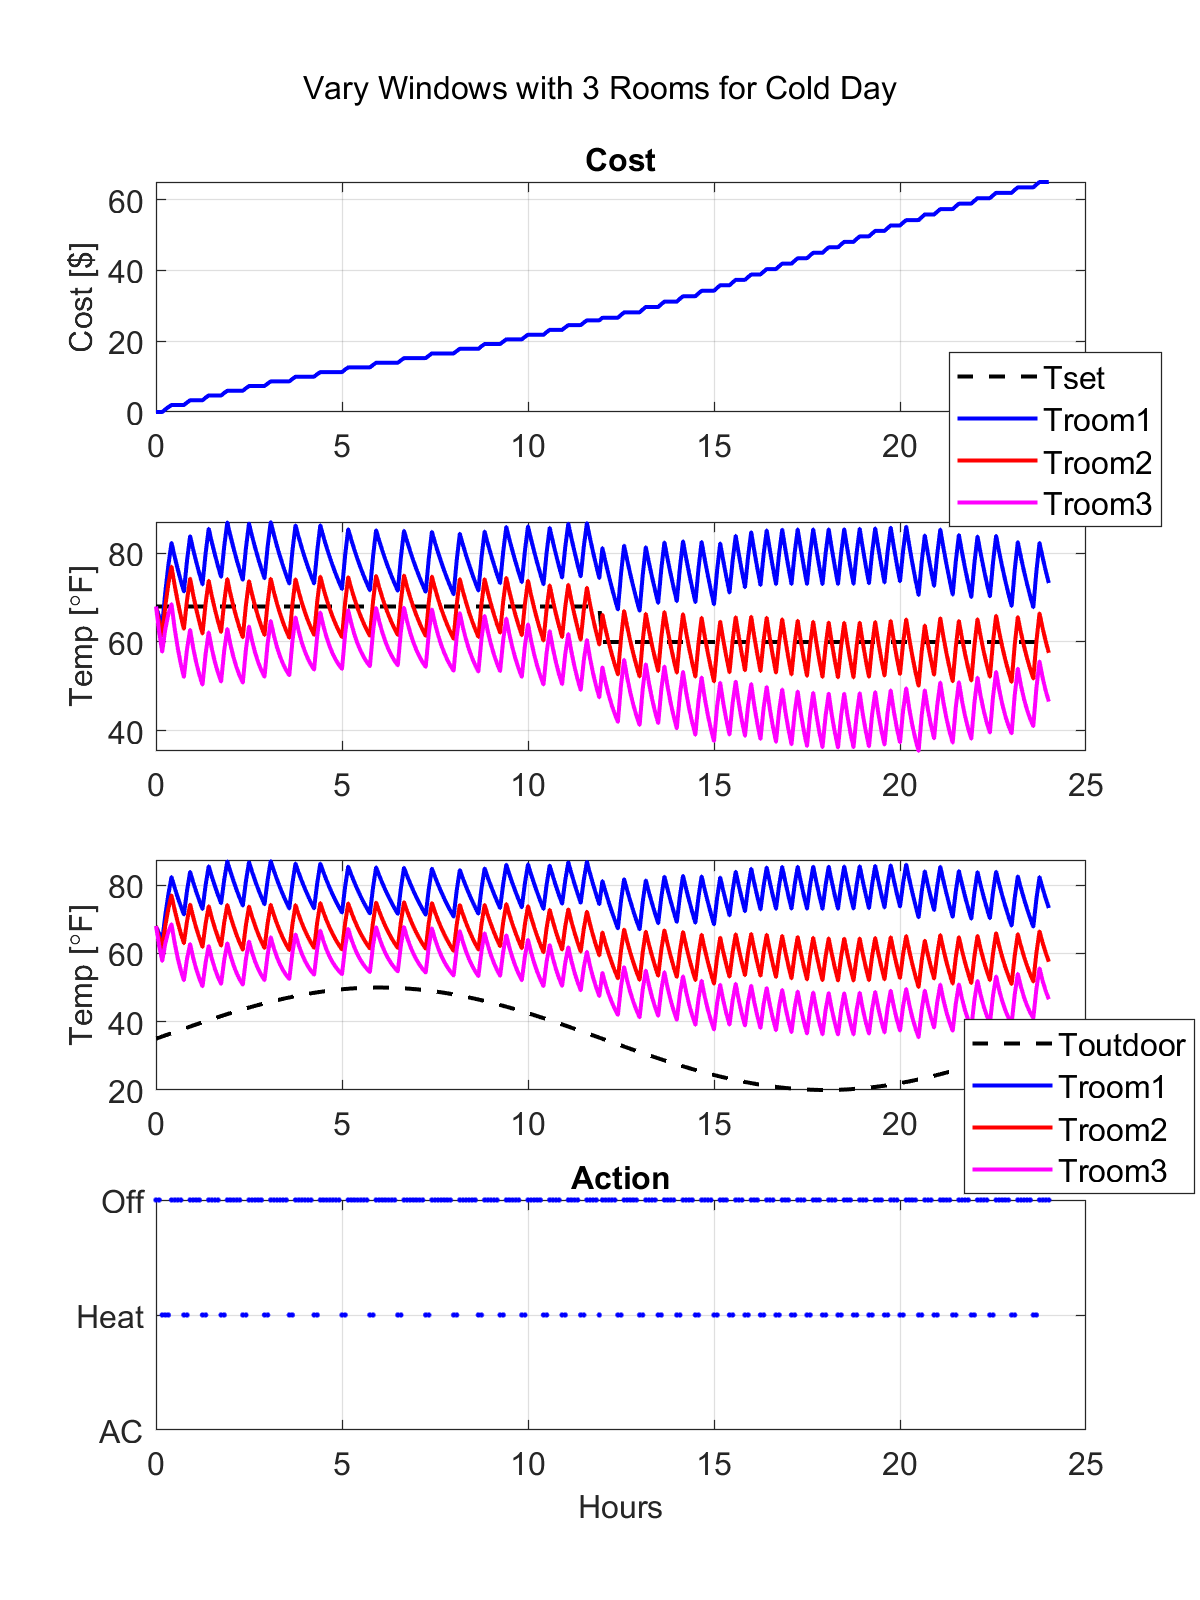


$$T_{outdoor}: 35 ^{\circ} F \\ 
T_{room1} \ mae: 14.0355 ^{\circ} F \\
T_{room2} \ mae: 3.572 ^{\circ} F \\
T_{room3} \ mae: 12.4326 ^{\circ} F \\
Cost: \$65 \\$$


Project Bonsai’s Machine Teaching can learn a controller to maintain comfort for one room just like the benchmark. Instead of having the thermostat struggle to control an underactuated system with multiple rooms without considering cost, a brain may learn to generalize to seasons and multiple rooms with various number of windows through trial and error in simulation. The generalization can be incentivized to balance both comfort and cost. 

## Running the Model

There are two ways to run the model. The first is to use a thermostat, a classical method of maintaining temperature for buildings. This allows you to run the model without the connection to Bonsai to get an understanding of how controllable the system is for cost and comfort.

## Run Locally using Thermostat

To run the thermostat, first open the simulink model:

buildingEnergyManagement;

Then, select the Variant Subsystem called Controller (double-click the Variant Subsystem to see the pop-up menu):

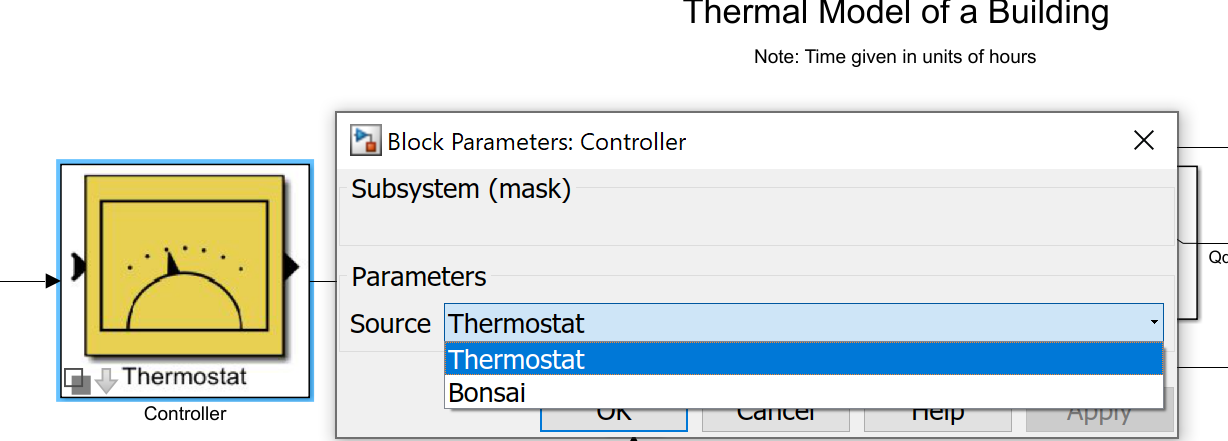

Now, after selecting **Thermostat** and clicking OK, you can run the benchmark script:

run_benchmark;

### Benchmark Scenarios

After running this command, the thermostat will be run under various scenarios:

- Normal day with $T_{out} = 60 ^{\circ} F$ sinusoid and changing set point temperatures, 1 room with 6 windows

- Hot day with $T_{out} = 95 ^{\circ} F$ sinusoid and changing set point temperatures, 1 room with 6 windows

- Cold day with $T_{out} = 35 ^{\circ} F$ sinusoid and changing set point temperatures, 1 room with 6 windows

- Plot showing varying number of window's effect on heat losses

- Normal day with $T_{out} = 60 ^{\circ} F$ sinusoid and changing set point temperatures, 3 room with 3, 6, 12 windows

- Hot day with $T_{out} = 95 ^{\circ} F$ sinusoid and changing set point temperatures, 3 room with 3, 6, 12 windows

- Cold day with $T_{out} = 35 ^{\circ} F$ sinusoid and changing set point temperatures, 3 room with 3, 6, 12 windows

You will need to Press 'Enter' to continue to in the Command Window to progress from one scenario to the next.

### Modifying Parameters

Each scenario focuses on changing the initial outdoor temperature for the mean of the sinusoid to simulate different seasons. Investigating control initially begins with one room that has 6 windows. Then parameters such as the number of rooms and number of windows are scaled to increase complexity.

To modify values for the thermostat, essentially write to the base workspace by editing values in `run_benchmark.m`  and run the relevant section. 

When `n_rooms` is specified to be a single room, the temperatures for room 2 and room 3 will always be reported as zero as specified in Simulink with the switches. 

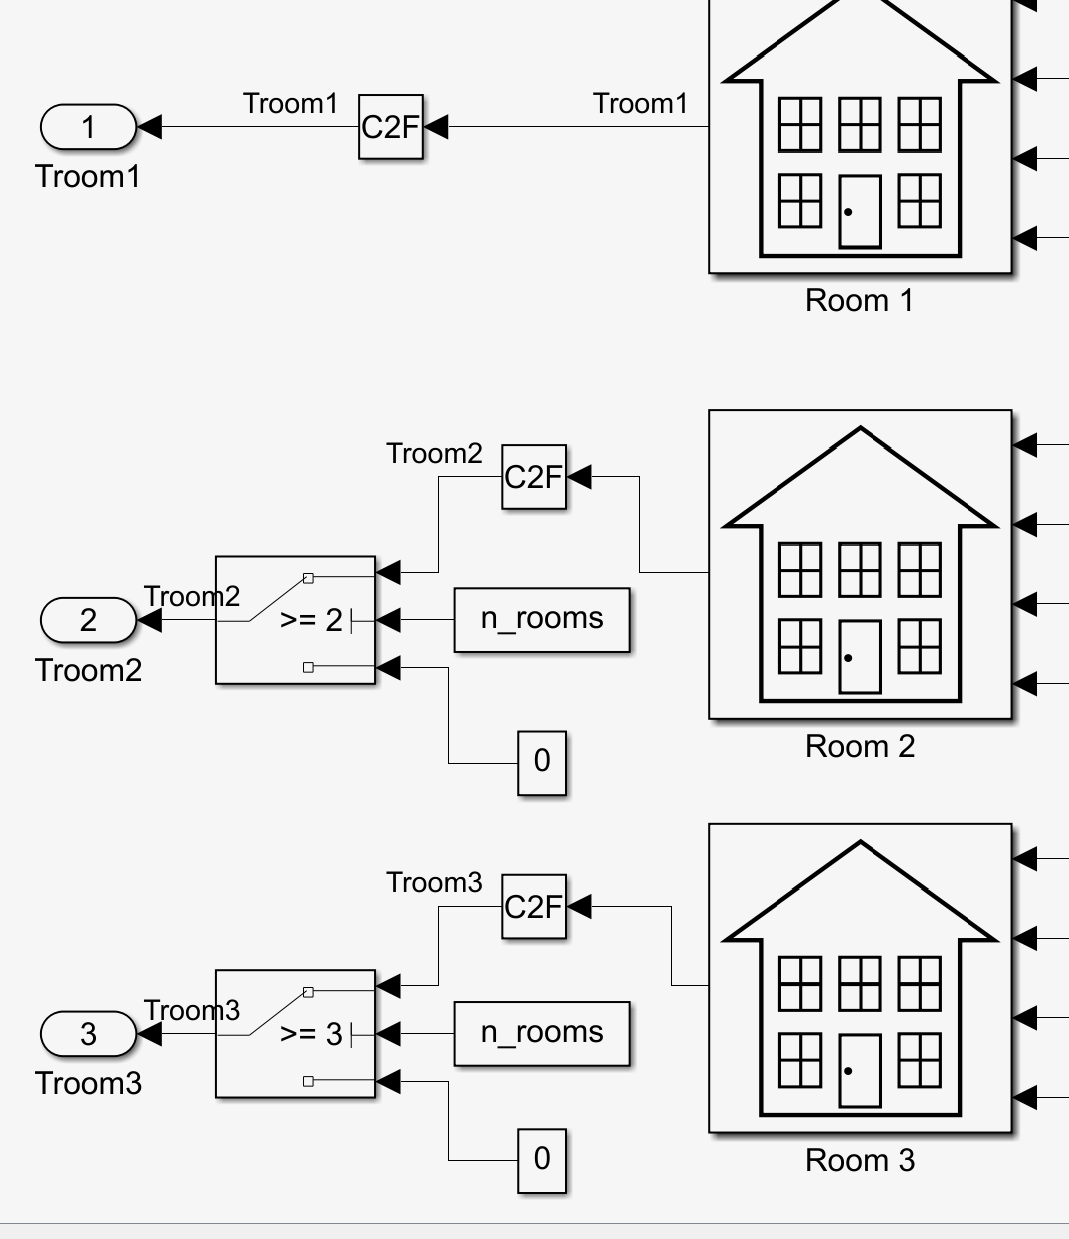

### Important!

To make sure that you don't run into issues when training with Bonsai, make sure to always run the 2nd to last section of `run_benchmark.m`.

%% Return values to default

n_rooms =  1;
nWindows_room1 = 6;
nWindows_room2 = 6;
nWindows_room3 = 6;

init_vars

## Run Locally using Bonsai Controller

After getting acclimated with the Building Energy Management model and setting up a Bonsai account, you are now ready to train your first Bonsai brain for this simulation. Be sure to select **Bonsai** in the Controller block and save your model.

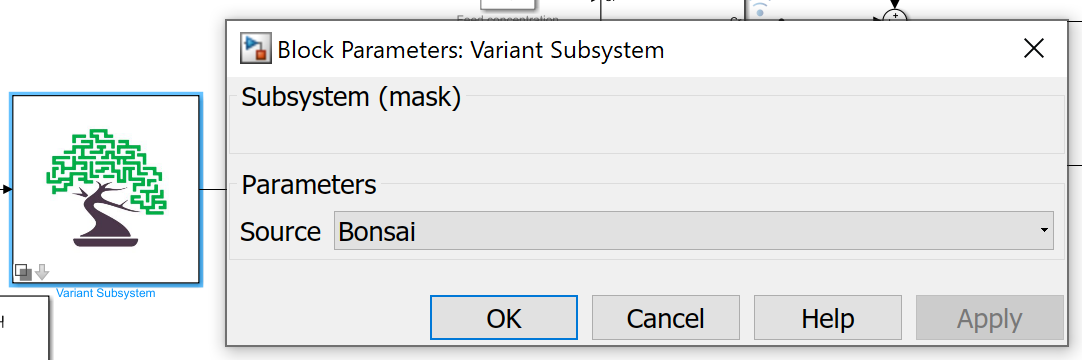 

Be sure to **Save** and **Close** the model with the Bonsai Controller selected.

### Connect to Bonsai

If you have not done so, you will need to create a Bonsai [account](https://docs.microsoft.com/en-us/bonsai/quickstart/setup). 

From the Bonsai UI, you will need to capture your Bonsai **Workspace ID **and **Access Key**.

#### Create a Brain

In the Bonsai UI click `+Create Brain:`

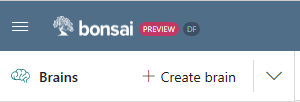

This will prompt for the type of brain to create:

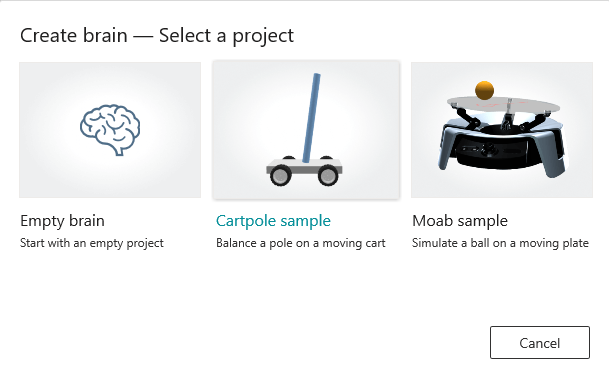

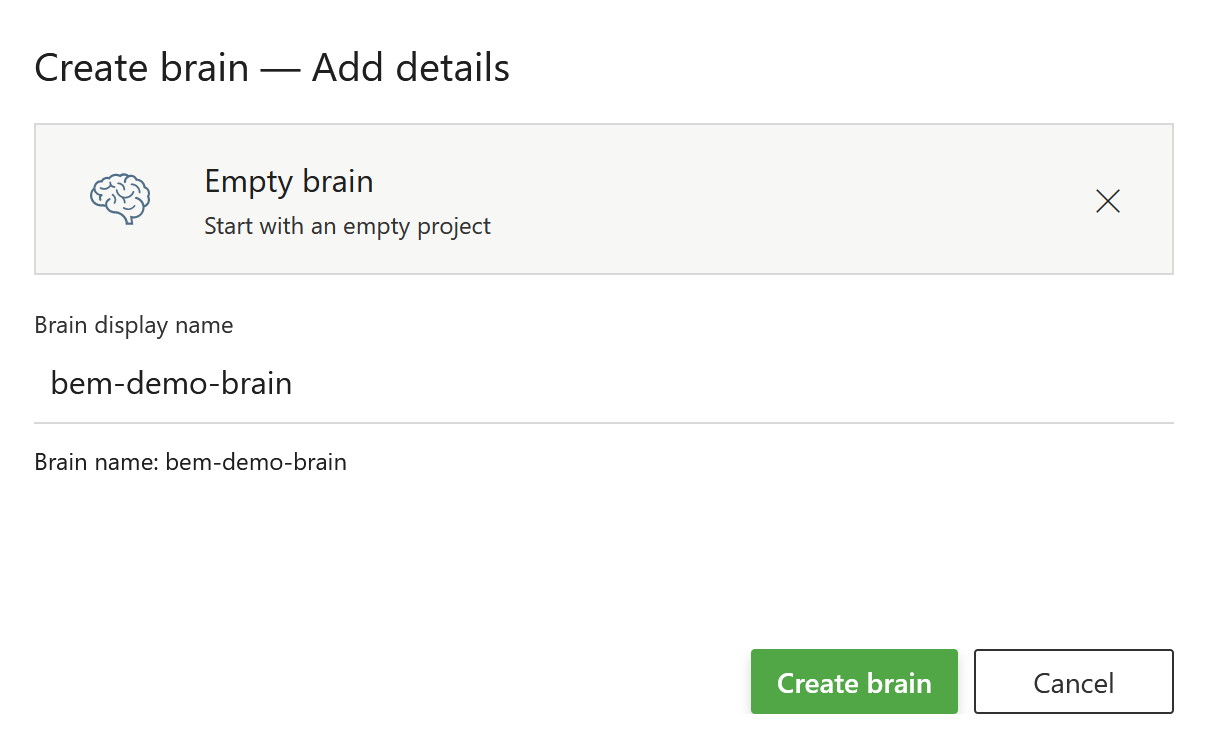

In this example, the brain is called **bem**`-demo-brain``. `Click the `Create brain` button`.`

This will create your brain and take you to the **Teach** tab:

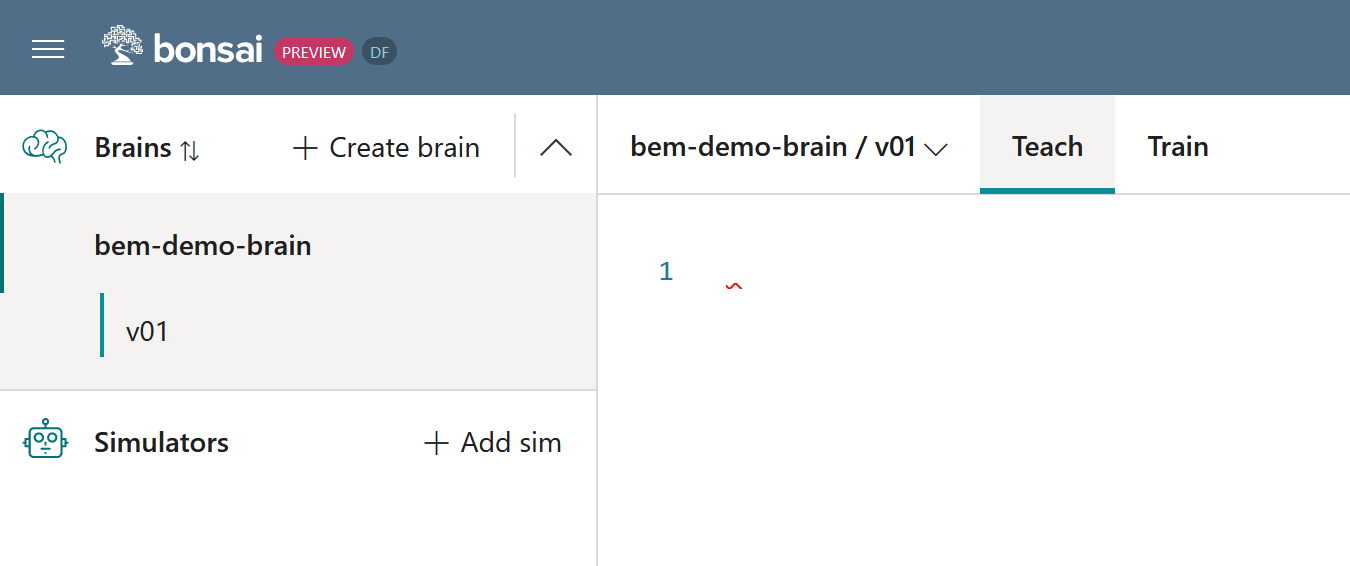

Note, the Inkling file will be empty in this case (in contrast with Moab and Cartpole samples). Now open the `bem_tutorial_1.ink` file. Copy the full content ("CTRL+a", then "CTRL+c") and paste it in the web.

You are now ready to train locally with the Bonsai Controller.

### The `bonsaiConfig `File

The `bonsaiConfig` function is used to setup the connection between your model and the Bonsai platform. Here you describe several key factors:

- **name** - The name of your simulator (you will see this when you connect to Bonsai)

- **url** - Optional. The URL used to connect the Bonsai API service

- **timeout** -- Optional. The value in seconds for a timeout. A default value of 60 seconds is used if this is not explicitly set. **If you receive timeouts when running bonsaiTrain, increase this value up to 300**.

- **workspace** - The workspace value obtained from the Bonsai platform.

- **accessKey** - the access key obtained from the Bonsai platform.

- **outputCSV** - Optional. When running locally, this can be helpful for debugging your model and the Bonsai connection.

- **stateSchema** - *Important. *This is the *order* of the values as they appear in the input parameter of the Bonsai block. Even if you use a Bus as your input the Bonsai block must understand the order of the values. These names must match what is in your inkling code in Bonsai. 

- **actionSchema** - The actions the brain will perform. Input ports to the Moab subsystem. The names must match what is in your inkling code from Bonsai. Order is important. 

- **configSchema** - The values that the Bonsai brain will send during a training episode. These are used as configuration parameters to initialize the model with different states, such as ball size, position, or velocity. 

**Note:** Your model may contain more states than what is in your inkling code for Bonsai. It is OK to have additional states that you send - these are ignored by the platform during execution. However, you must send all states that are required by the inkling code. If you do not, you will receive an error from the platform with an immediate Unregister command.

### Edit `bonsaiConfig`

Now open the `bonsaiConfig` file and replace 

`<your workspace here>` with your Workspace ID 

`<your access key here>` with your Access Key (*not *key ID)

% add workspace id
% add access key

edit bonsaiConfig;


You do not need to change any other values other than `workspace` and `accessKey. Another option is to set up environment variables for SIM_WORKSPACE and SIM_ACESS_KEY to prevent accidentally saving credentials into code revision.`

### `Run Bonsai Training with a Single Local Instance`

Now that the connection to Bonsai has been configured, run the `bonsaiTrain` function.

bonsaiTrain; 

Once you see the Sim successfully registered message in the MATLAB Command Window, switch over to the [Bonsai UI](http://preview.bons.ai), click the `Train` button`. `

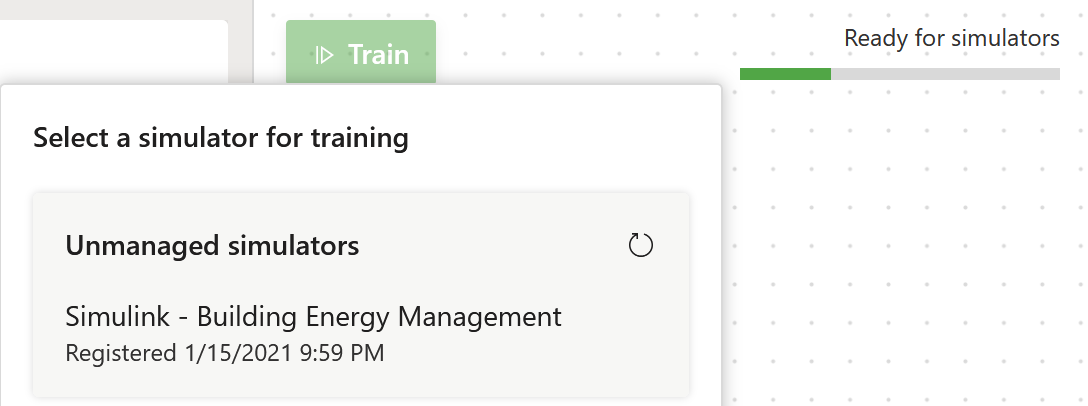

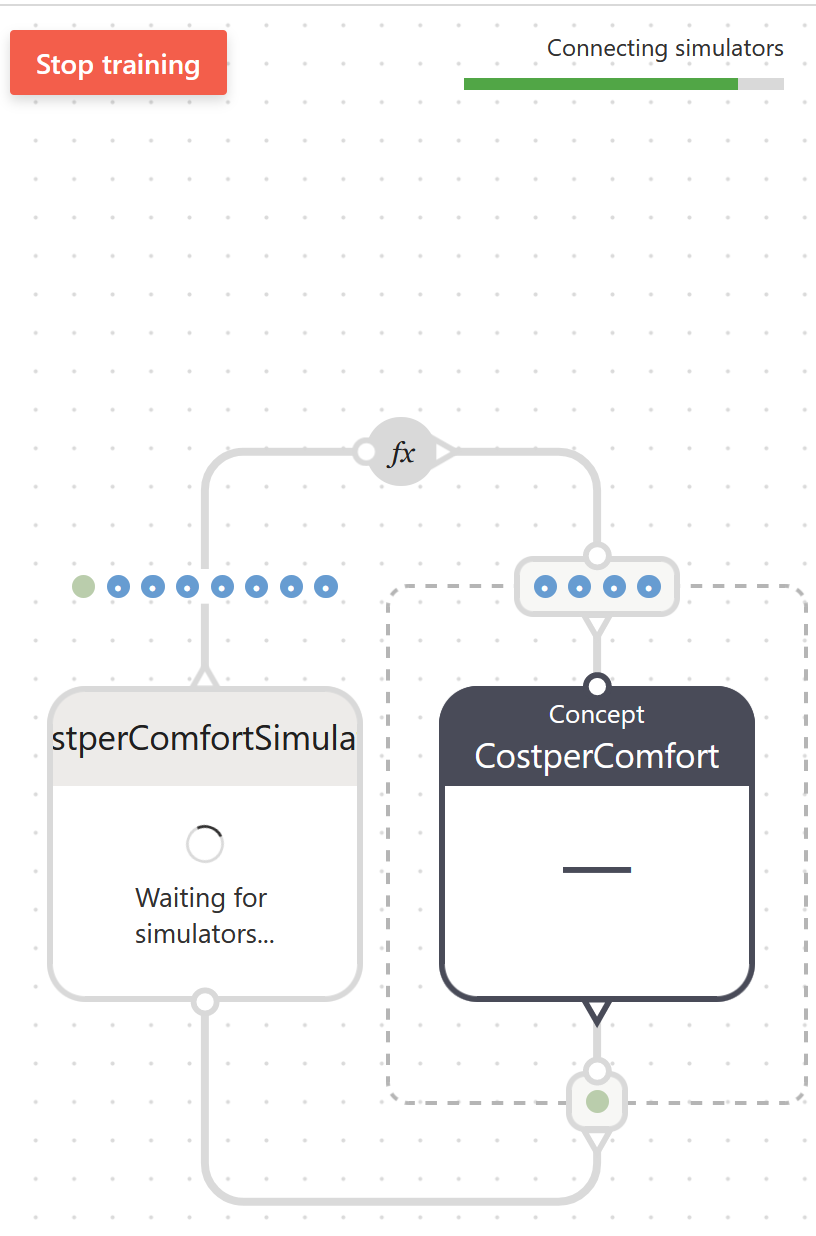

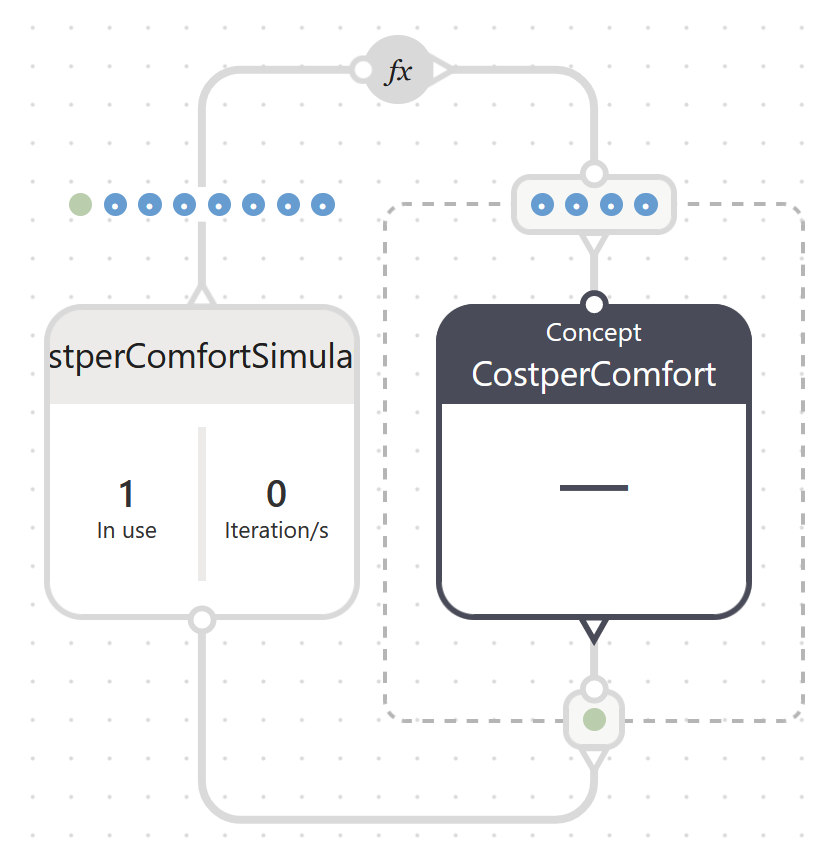

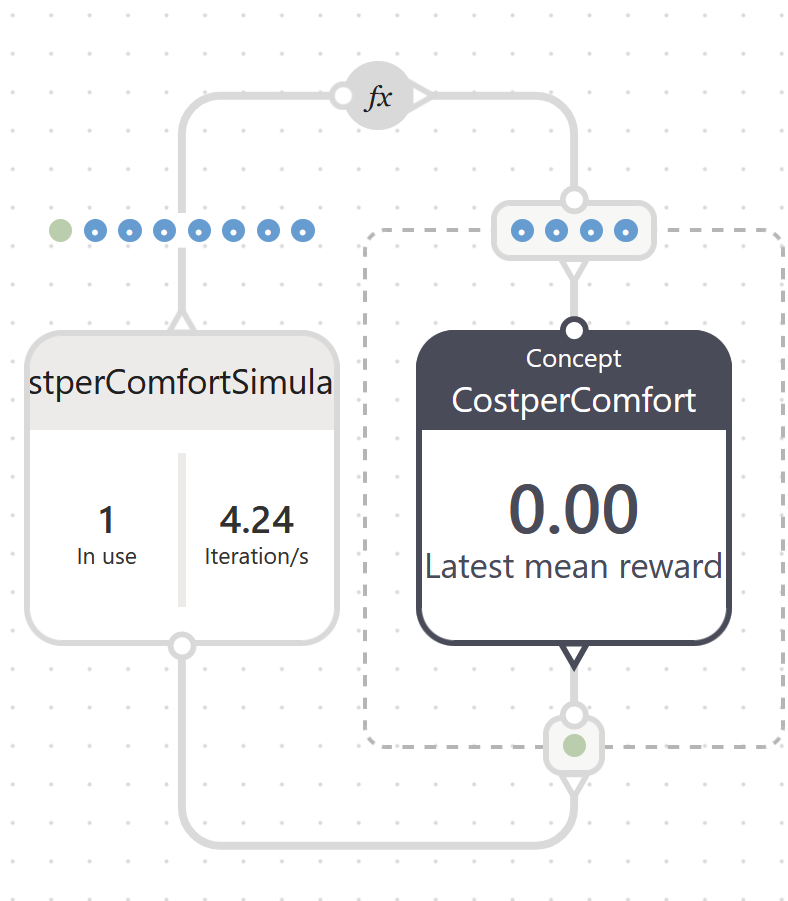

Check the MATLAB Command Window to see a series of outputs indicating communication with the Bonsai brain.

Connection speeds vary, but this model mostly operates at about 3-7 iterations per second. 

To stop training, click `Stop Training `in the Bonsai UI.

**Note:** To terminate the simulation in MATLAB, use Ctrl+C in the Command Window. Be sure to disable Fast Restart from the Simulation tab in the Simulink model.

## Zip, Upload and Scale Your Model

Scaling the model greatly improves training times. Once you have verified your model connects locally, you can close Simulink and zip the entire contents of the folder that contains the model. 

For example, if your folder structure is:

`building_energy_management`

`└─── img`

`|    └── ... image files ... `

`|─── bonsaiAssess.m`

`|─── bonsaiConfig.m`

`|─── bonsaiTrain.m`

`|─── Building_Energy_Management.mlx`

`|─── building_Energy_Management.slx`

`|─── bem_tutorial_1.ink`

`|─── bem_tutorial_2.ink`

`|─── init_vars.m`

`|─── LICENSE`

`|─── README.md`

`└─── run_benchmark.m`

Then you only need to zip the parent **building_energy_management** folder. It is suggested you remove your` slprj` folder and` .slxc `files before zipping up the folder contents. You also do not need any` .csv `files, neither the `img/` folder`. `Call the file building_energy_management`.zip. `

### Upload the Model

Back in the Bonsai UI, next to `Simulators``,` click the `Add sim` button.

This will open a dialog:

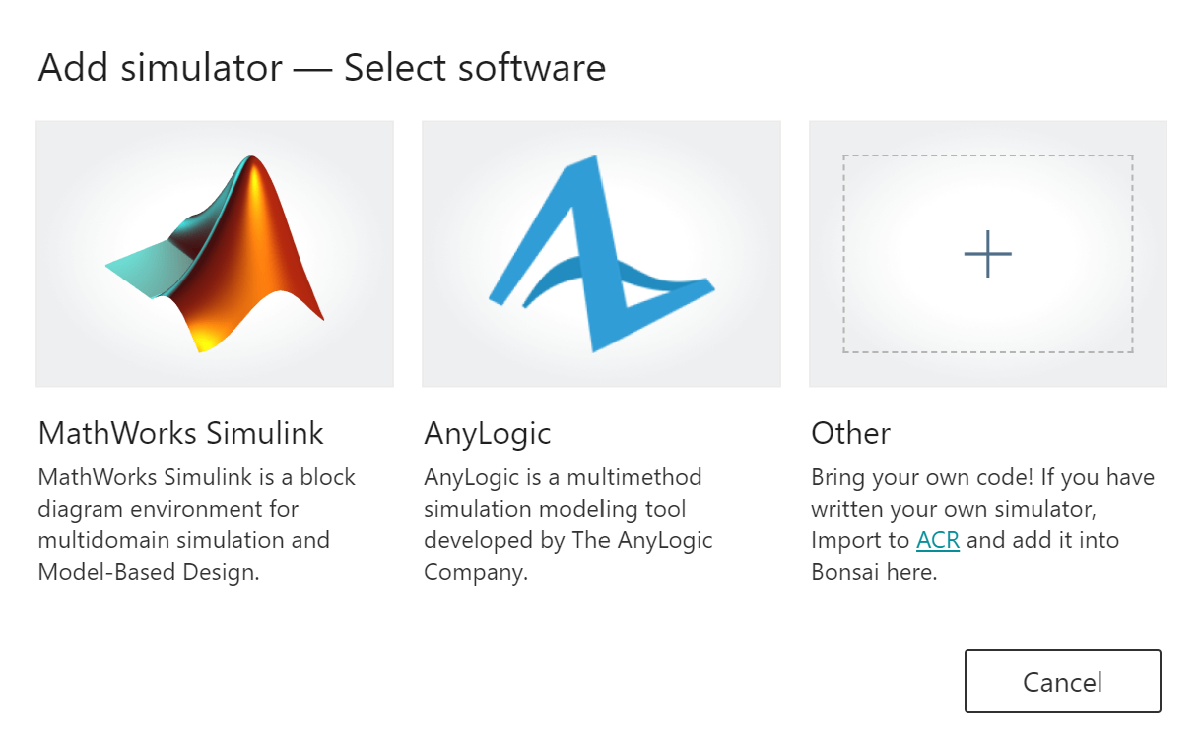

Select `MathWorks``. `Then you can upload your zip file`:`

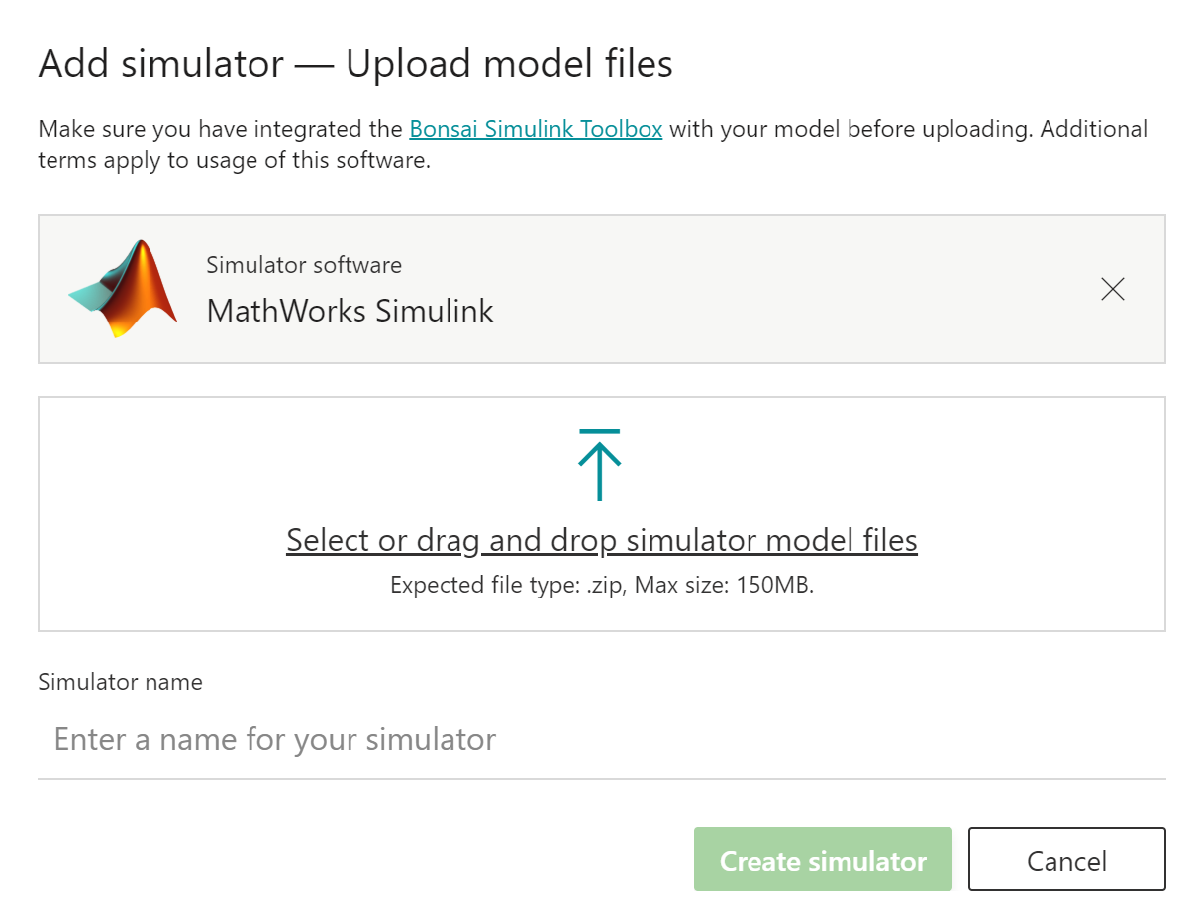

Select or drag the building_energy_management`.zip `file created previously`.`

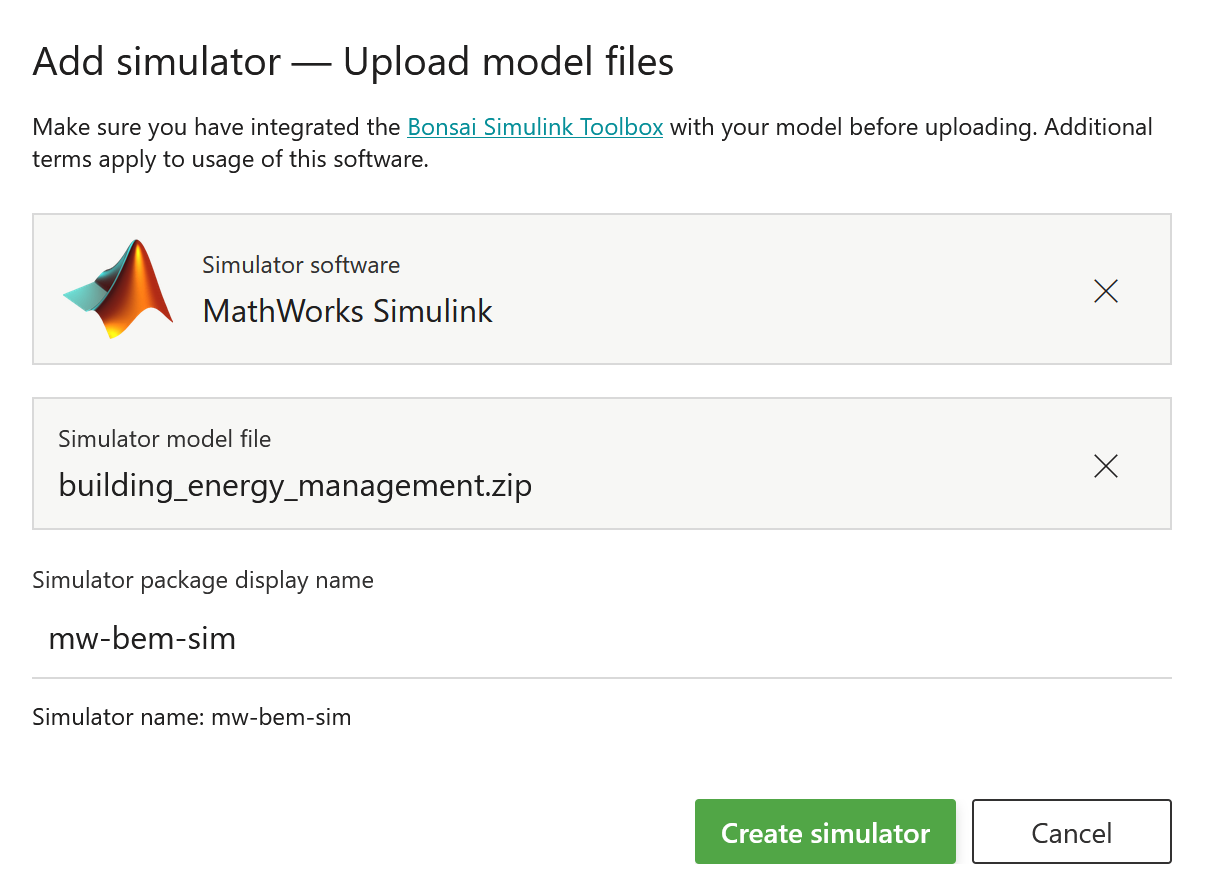

Give your simulator a name, then click `Create simulator``. `

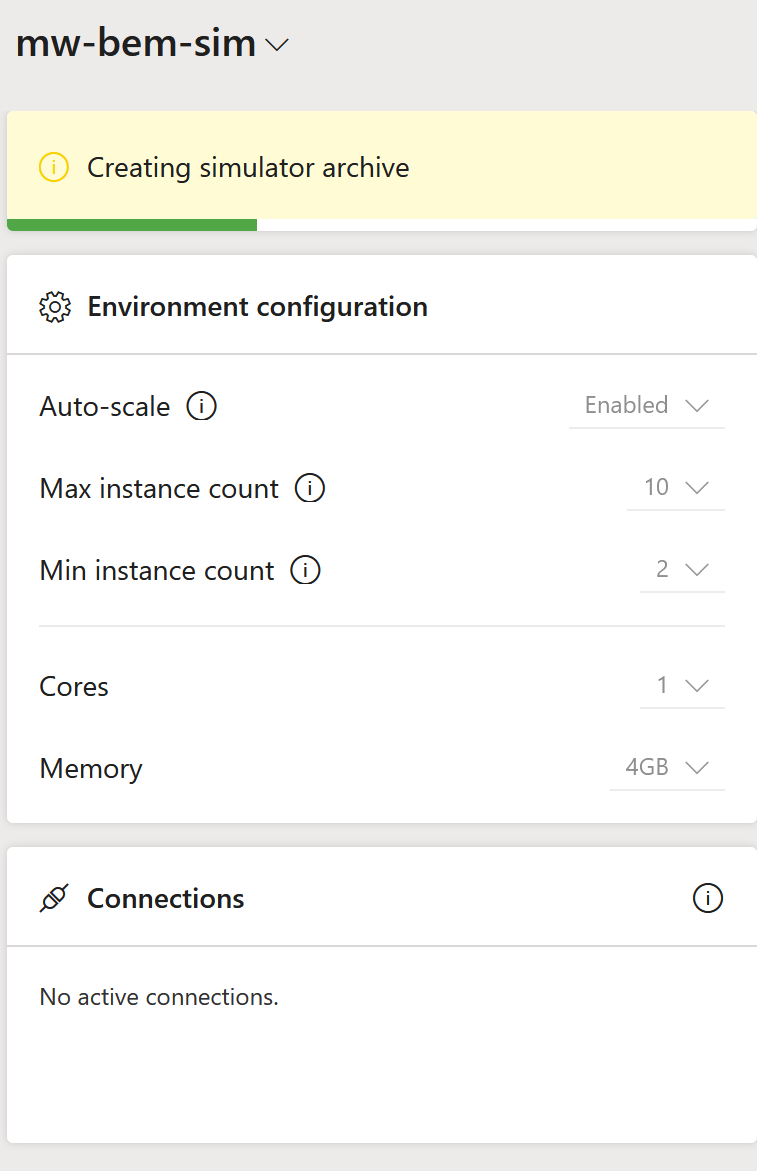

**Note: ***It may take up to 20 minutes to create the simulator image. *You will the ACR path displayed after successful creation:

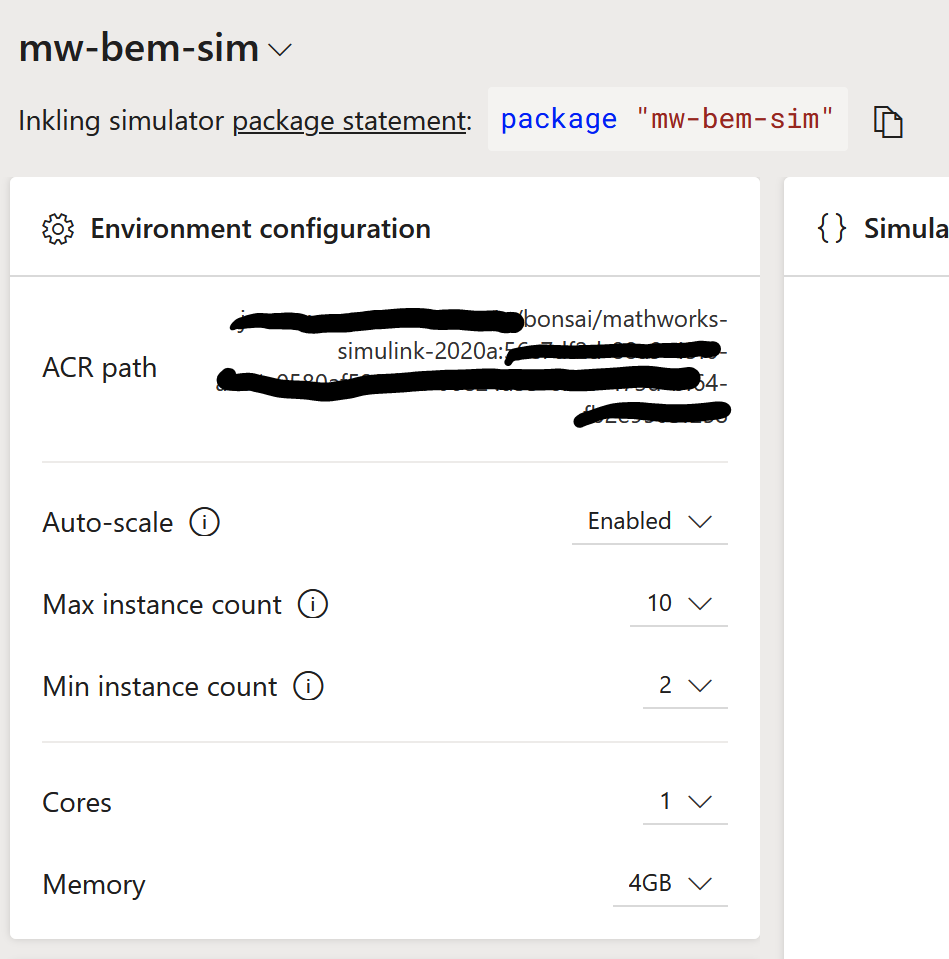

After the simulator is created you will see the new simulator appear under the `Simulators`` section.`

**Note: **Be sure your brain is not training prior to changing the package statement.

Now click the `Teach` tab. 

In the simulator definition in Inkling ("teach" tab on https://preview.bons.ai), you will need to include the name of the simulator you gave during the Add Simulator dialog above.

### Scale Your Training

Now click the `Train` button for your brain. This will create several instances (from 1-50) using your uploaded model to train your brain.

**Note: **It may take up to 10 minutes for your simulators to connect.

## Assessing Brain Performance

Assessment allows you to test the performance of a trained brain while still hosting that brain in the Bonsai platform. 

After training your brain(s) you will want to assess their performance. Make sure your Bonsai Controller is enabled in Simulink. Run:

bonsaiAssess;

This will begin assessment and connect to the Bonsai platform, similar to training. If your model is not open this will also open the model.

Click the `Run` button in Simulink.

In the Bonsai UI, click the `Start Assessment `button.

If the package statement is still in Inkling, it will use a managed simulation for Assessment. If you wish to run an unmanaged simulator from your personal computer, uncomment the package statement. Then click the `Simulink - Building Energy Management` simulator. 

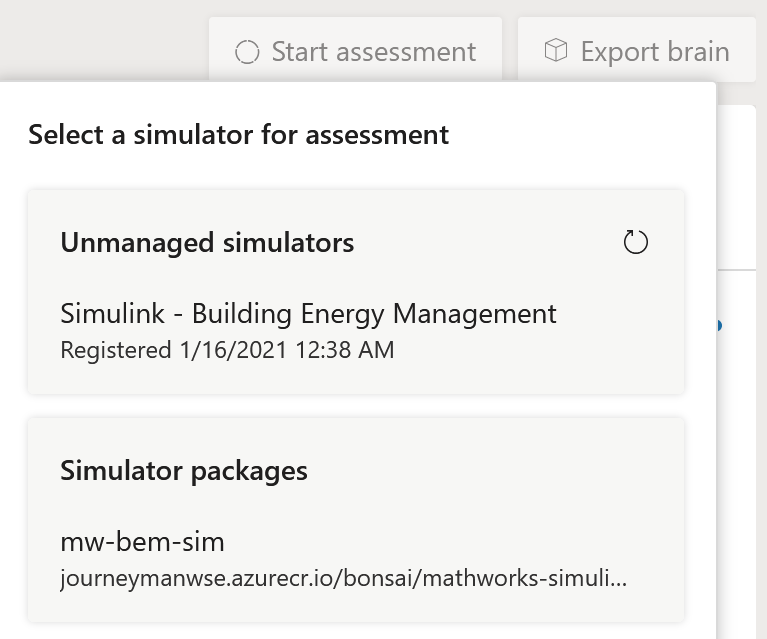

Your local model will iterate using the brain in assessment mode.

If you receive the message `Last event was Unregister, done requesting events `then you may need to increase the timeout value in bonsaiConfig.

## Inkling files

There are two Inkling files included with this Building Energy Management sample. Tutorial 1 focuses on balancing cost and comfort for a single room with 6 windows. Tutorial 2 considers the same objective, but now with 3 rooms with different number of windows.